# ENERGY CONSUMPTION PREDICTION

Nombre: Jose Rodolfo Valencia Mosquera, Fabio Elias Mera Guadamud[](https://orcid.org/0000-0002-3539-5482)

- Referencia: [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- `SRC: `[https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `DataPort: `

- Sampling Rate=1Hz

- Date = '2021-05-06 00:00:00' AND '2021-11-22 22:04:21'

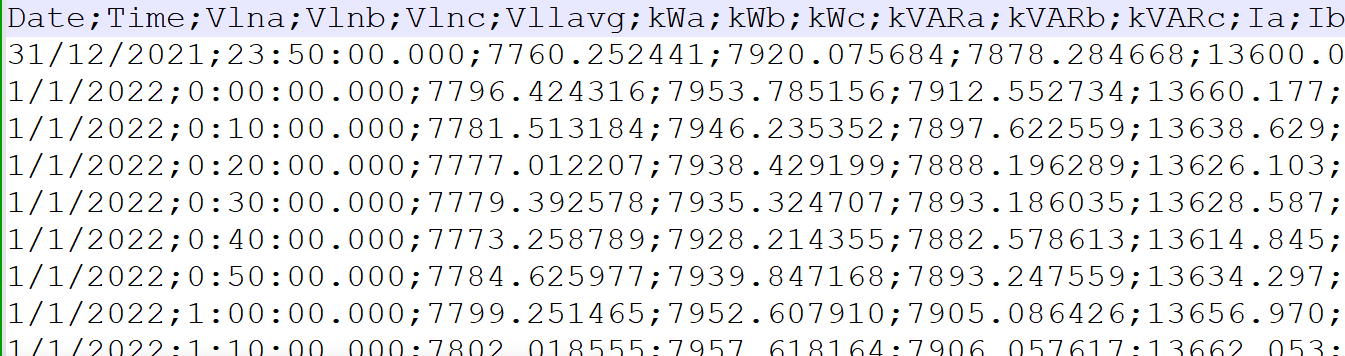

# 1- Load Raw Data

%Antes de ejercutar este codigo, reemplazar los espacios por ";"
clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
filenames = FindTXT(datapath);%List All CSV files
allData=[];
dataNew=[];

for i=1:length(filenames)% Through all files
    data=readtable(fullfile(datapath,filenames(i).name));%Select i CSV file
    %The first 3 columns are deleted: topic, server date, esp32 date, and esp32 date.
    
 dia = [1];
 mes = [2];
 ano = [3];
 Time = [4];
 VLna = [5];
 VLnb = [6];
 VLnc = [7];
 VLLavg = [8];
 kWa = [9];
 kWb = [10];
 kWc = [11];
 kVARa = [12];
 kVARb = [13];
 kVARc = [14];
 Ia = [15];
 Ib = [16];
 Ic = [17];
 kWtotal = [18];
 
     
 
%      data1=[data(:,1)];
%      %dataNew=table2cell(data);
%      dataNew1=table2array(data1);% Array to Double
%      dataNew1(isnan(dataNew1)) = 0;%Remove NAN numbers
%      dataNew=[dataNew,dataNew1];
%      
%      data2=[data(:,2)];
%      %dataNew=table2cell(data);
%      dataNew2=table2array(data2);% Array to Double
%      dataNew2(isnan(dataNew2)) = 0;%Remove NAN numbers
%      dataNew=[dataNew,dataNew2];
%      
%      data3=[data(:,3)];
%      %dataNew=table2cell(data);
%      dataNew3=table2array(data3);% Array to Double
%      dataNew3(isnan(dataNew3)) = 0;%Remove NAN numbers
%      dataNew=[dataNew,dataNew3];
     
      
     data5=[data(:,5)];
     %dataNew=table2cell(data);
     dataNew5=table2array(data5);% Array to Double
     dataNew5(isnan(dataNew5)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew5];
 
     data6=[data(:,6)];
     %dataNew=table2cell(data);
     dataNew6=table2array(data6);% Array to Double
     dataNew6(isnan(dataNew6)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew6];
     
     data7=[data(:,7)];
     %dataNew=table2cell(data);
     dataNew7=table2array(data7);% Array to Double
     dataNew7(isnan(dataNew7)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew7]; 
     
     data9=[data(:,9)];
     %dataNew=table2cell(data);
     dataNew9=table2array(data9);% Array to Double
     dataNew9(isnan(dataNew9)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew9];
     
     data10=[data(:,10)];
     %dataNew=table2cell(data);
     dataNew10=table2array(data10);% Array to Double
     dataNew10(isnan(dataNew10)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew10];
     
     data11=[data(:,11)];
     %dataNew=table2cell(data);
     dataNew11=table2array(data11);% Array to Double
     dataNew11(isnan(dataNew11)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew11];
     
     data12=[data(:,12)];
     %dataNew=table2cell(data);
     dataNew12=table2array(data12);% Array to Double
     dataNew12(isnan(dataNew12)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew12];
     
     data13=[data(:,13)];
     %dataNew=table2cell(data);
     dataNew13=table2array(data13);% Array to Double
     dataNew13(isnan(dataNew13)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew13];
     
     data14=[data(:,14)];
     %dataNew=table2cell(data);
     dataNew14=table2array(data14);% Array to Double
     dataNew14(isnan(dataNew14)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew14];
     
     data18=[data(:,18)];
     %dataNew=table2cell(data);
     dataNew18=table2array(data18);% Array to Double
     dataNew18(isnan(dataNew18)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew18];
     
       
     allData=[allData;dataNew];
     dataNew=[];
       
     
%     
%     data=[data(:,6)];
%     %dataNew=table2cell(data);
%     dataNew1=table3array(data);% Array to Double
%     dataNew1(isnan(dataNew1)) = 0;%Remove NAN numbers
%     allData1=[allData1;dataNew1];
    
end
%  creando la columna de energia
Energia = allData(:,10)./6;
allData = [allData Energia]

allData = 	1.0e+04 *

    0.7954    0.8007    0.8053    0.2932    0.3120    0.3090    0.0939    0.1008    0.1128    0.9143    0.1524
    0.7959    0.8008    0.8057    0.2910    0.3118    0.3083    0.0922    0.1023    0.1118    0.9111    0.1519
    0.7962    0.8018    0.8064    0.2896    0.3098    0.3060    0.0920    0.1008    0.1120    0.9053    0.1509
    0.7968    0.8021    0.8071    0.2885    0.3092    0.3006    0.0905    0.1018    0.1101    0.8982    0.1497
    0.7975    0.8030    0.8080    0.2866    0.3092    0.3002    0.0918    0.1026    0.1100    0.8959    0.1493
    0.7978    0.8036    0.8082    0.2880    0.3016    0.2965    0.0911    0.1018    0.1109    0.8860    0.1477
    0.7980    0.8040    0.8086    0.2837    0.2993    0.2965    0.0918    0.1003    0.1095    0.8795    0.1466
    0.7844    0.7899    0.7944    0.2746    0.2913    0.2873    0.0828    0.0935    0.1008    0.8532    0.1422
    0.7884    0.7937    0.7978    0.2672    0.2841    0.2782    0.0820    0.0925    0.0999


clear data dataNew;


# 2- Plot Raw Data

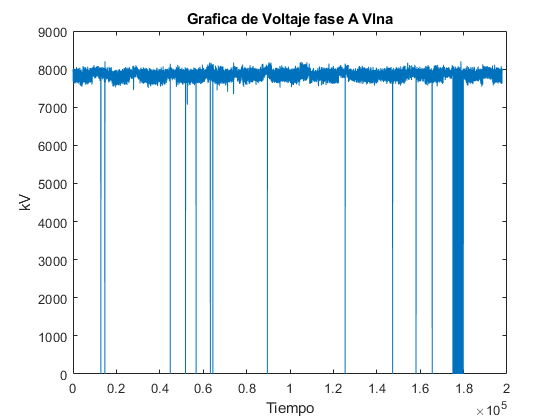

plot(allData(:,1));
title('Grafica de Voltaje fase A Vlna');
xlabel('Tiempo');
ylabel('kV');


% se resumen la tabla, la columna 16 se convierte en la 5


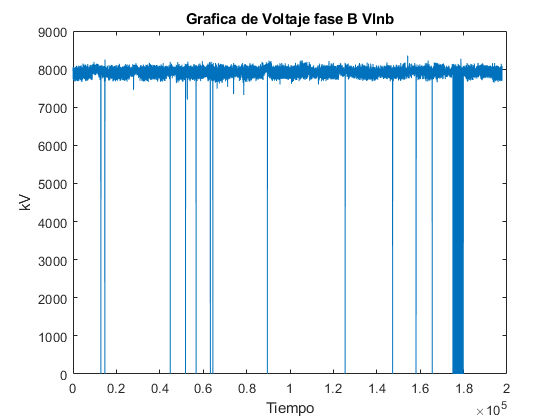

plot(allData(:,2));
title('Grafica de Voltaje fase B Vlnb');
xlabel('Tiempo');
ylabel('kV');

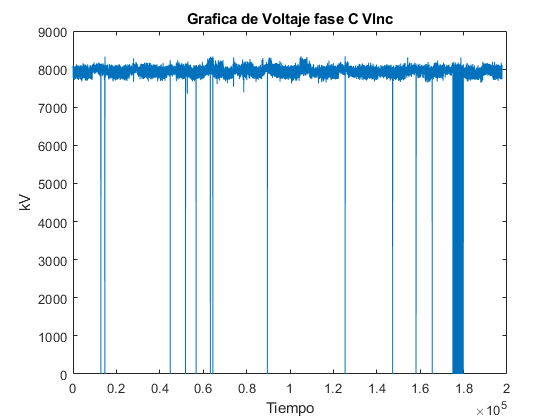

plot(allData(:,3));
title('Grafica de Voltaje fase C Vlnc');
xlabel('Tiempo');
ylabel('kV');

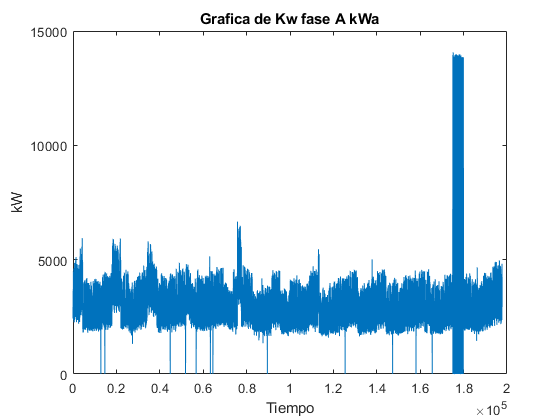

plot(allData(:,4));
title('Grafica de Kw fase A kWa');
xlabel('Tiempo');
ylabel('kW');

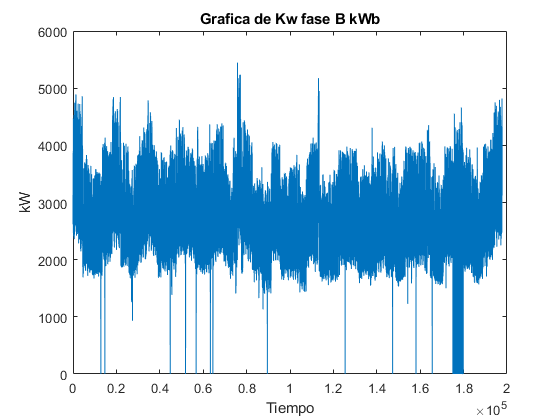

plot(allData(:,5));
title('Grafica de Kw fase B kWb');
xlabel('Tiempo');
ylabel('kW');

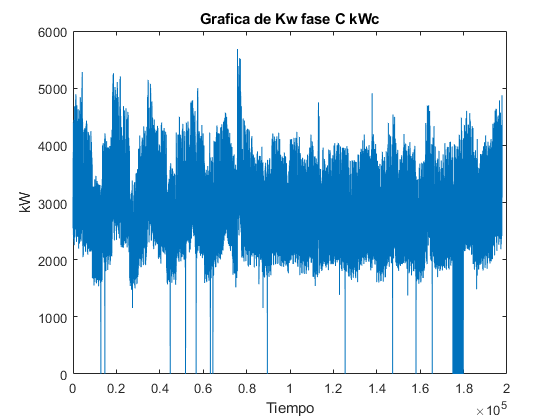

plot(allData(:,6));
title('Grafica de Kw fase C kWc');
xlabel('Tiempo');
ylabel('kW');

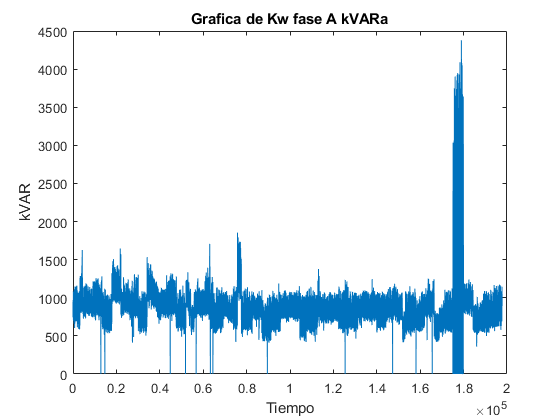


plot(allData(:,7));
title('Grafica de Kw fase A kVARa');
xlabel('Tiempo');
ylabel('kVAR');

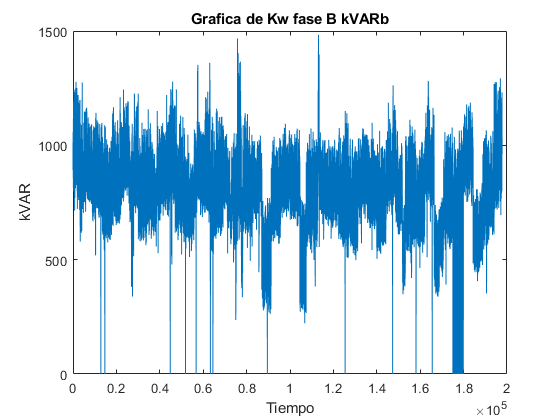

plot(allData(:,8));
title('Grafica de Kw fase B kVARb');
xlabel('Tiempo');
ylabel('kVAR');

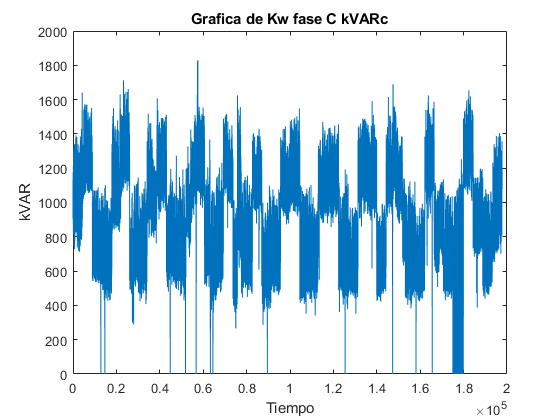


plot(allData(:,9));
title('Grafica de Kw fase C kVARc');
xlabel('Tiempo');
ylabel('kVAR');

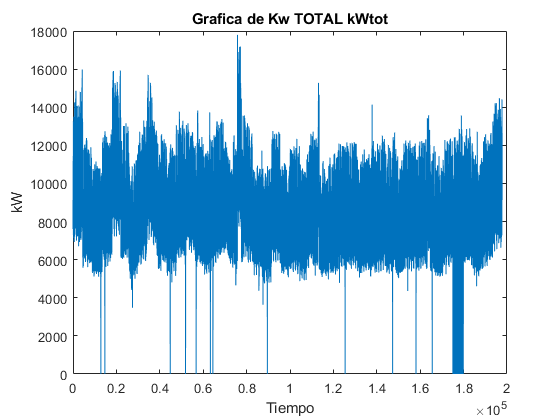

plot(allData(:,10));
title('Grafica de Kw TOTAL kWtot');
xlabel('Tiempo');
ylabel('kW');

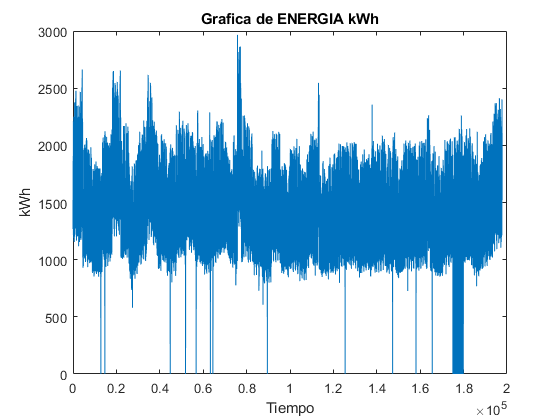

plot(allData(:,11));
title('Grafica de ENERGIA kWh');
xlabel('Tiempo');
ylabel('kWh');

# 3. Preprocesamiento de datos 

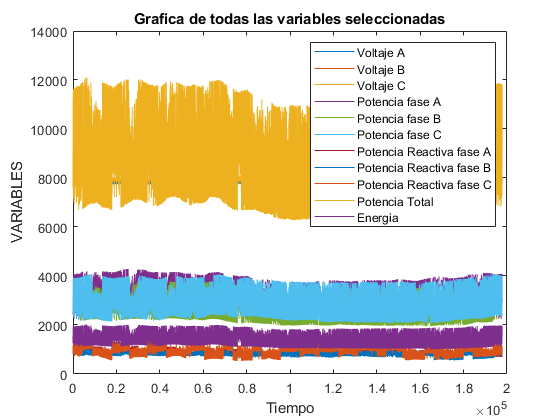

y = hampel(allData,15000,1);
plot (y)
%plot(allData1);
title('Grafica de todas las variables seleccionadas');
xlabel('Tiempo');
ylabel('VARIABLES');
legend('Voltaje A','Voltaje B','Voltaje C','Potencia fase A','Potencia fase B','Potencia fase C','Potencia Reactiva fase A','Potencia Reactiva fase B','Potencia Reactiva fase C','Potencia Total','Energia')

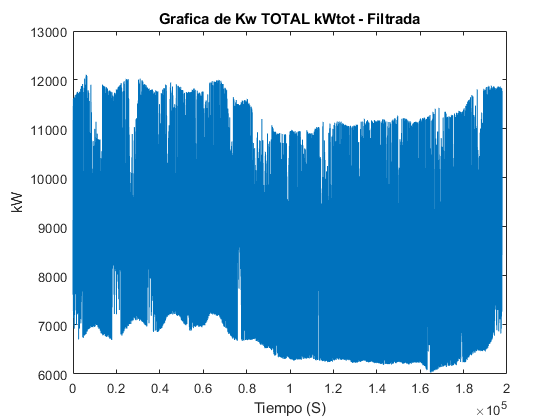

plot (y(:,10))
title('Grafica de Kw TOTAL kWtot - Filtrada');
xlabel('Tiempo (S)');
ylabel('kW');

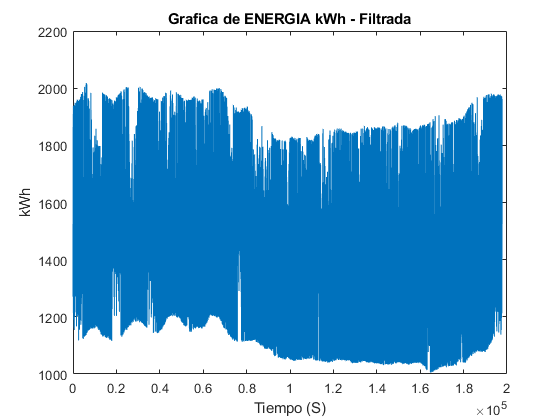


plot (y(:,11))
title('Grafica de ENERGIA kWh - Filtrada');
xlabel('Tiempo (S)');
ylabel('kWh');

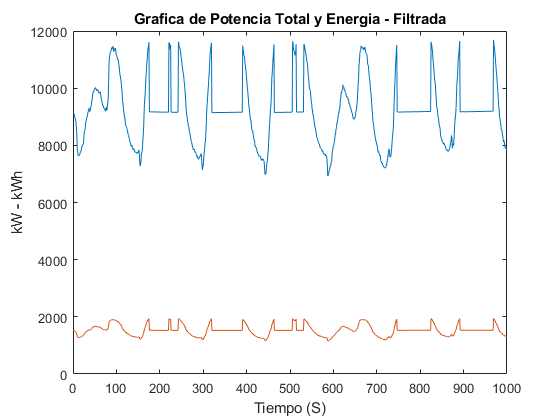


plot (y(1:1000,10))
hold on
plot (y(1:1000,11))
hold off
title('Grafica de Potencia Total y Energia - Filtrada');
xlabel('Tiempo (S)');
ylabel('kW - kWh');

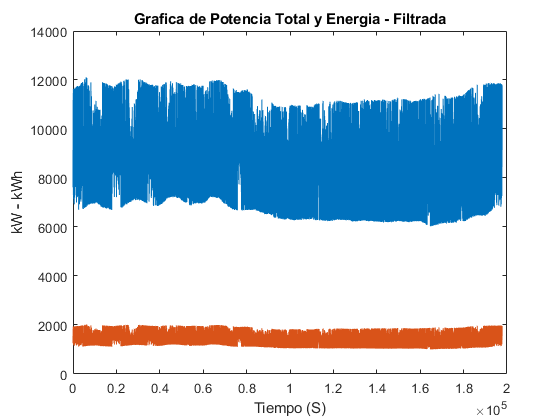

plot (y(:,10))
hold on
plot (y(:,11))
hold off
title('Grafica de Potencia Total y Energia - Filtrada');
xlabel('Tiempo (S)');
ylabel('kW - kWh');

# 4 SELECCION DE CARACTERISTICAS

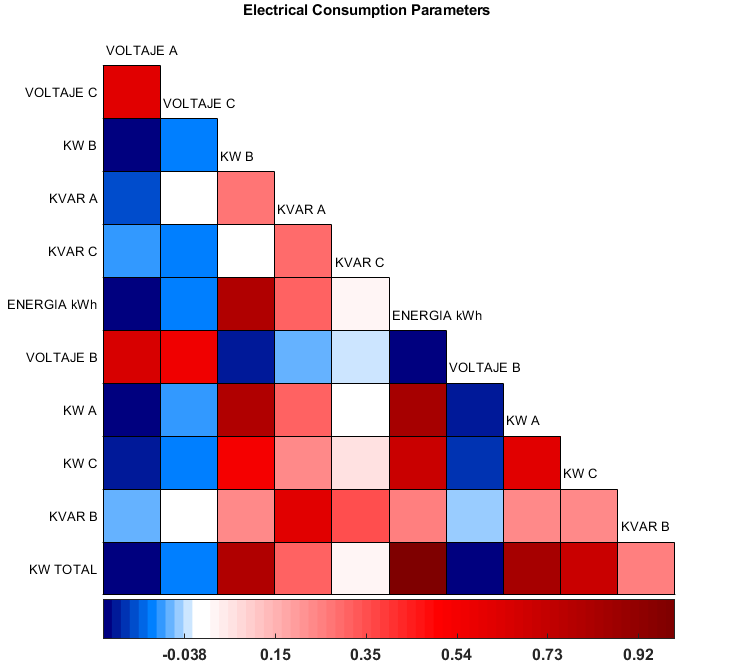


%corrplot(DataNorm)
%R = corrcoef(y)
threshold = 0.85;%75<-------Maximum correlation value allowed
% Labels:
FeaturesLabels = {'VOLTAJE A','VOLTAJE B','VOLTAJE C','KW A','KW B','KW C','KVAR A','KVAR B','KVAR C','KW TOTAL','ENERGIA kWh'};
    [NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(y,FeaturesLabels,threshold);

LabelsRemove(:)

ans = 2×1 cell array
    {'KW TOTAL'   }
    {'ENERGIA kWh'}


# 5 Identification

% input=[];output=[];
% % inputs: 'Potencia Total (kW)'
% input=allData(1:round(length(allData))-1,10);
% % output: Energía in the following time step
% output=allData(1+1:round(length(allData)),10);
% systemIdentification

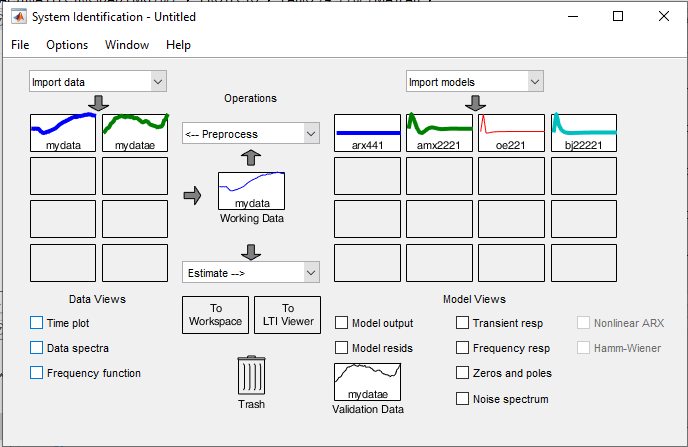

# FUNCION DE TRANSFERENCIA

% %% Función de Transferencia obtenida
% oe221=load('oe221.mat');%<---Modelo con mejor FIT del taller # 2
% oe221=oe221.oe221; % Convertir la estructura a un tipo idpoly
% G=tf(d2c(oe221));%Convertir la ecuacion de discreto a continuo
% 
% num=cell2mat(G.numerator);%Descomponer los parametros del numerador en un vector de valores
% den=cell2mat(G.denominator);%Descomponer los parametros del denominador en un vector de valores
% FTenergia=tf(num,den)%Conversion a ecuacion

# ENTRENAMIENTO DE MODELO DE PREDICCION

% %Dataset de entrenamiento
% input_train=[];output_train=[];
% % inputs: 'Potencia Total (kW)'
% input_train=allData(1:round(length(allData)*0.7)-1,10);
% % output: Energía in the following time step
% output_train=allData(1+1:round(length(allData)*0.7),10);
% % RegressionLinear
% input_train=hampel(input_train,200,1);
% output_train=hampel(output_train,200,1);
% Data_train=[input_train output_train];
% %%
% 
% 
% %Dataset de validacion
% input_val=[];output_val=[];
% % inputs: 'Potencia Total (kW)'
% input_val=allData(round(length(allData)*0.7):length(allData)-1,10);
% % output: Energía in the following time step
% output_val=allData(round(length(allData)*0.7)+1:length(allData),10);
% % Regression Learner
% input_val=hampel(input_val,200,1);
% output_val=hampel(output_val,200,1);
% Data_val=[input_val output_val];


# Cambio de ventana temporal de tiempo a hora. 

# Los modelos generados requieren como entrada valores promediados de una hora y predicen el valor promedio de la siguiente hora. 

% win=6;% 1 hora 
% %It takes time to iterate the number of samples / time window.
% allDataMean = fData_MeanWin(allData(:,10),win);
% 
% %Dataset de entrenamiento
% input_train_2=[];output_train_2=[];
% % inputs: 'Potencia Total (kW)'
% input_train_2=allDataMean(1:round(length(allDataMean)*0.7)-2,1);
% input_train_2_2=allDataMean(1+1:round(length(allDataMean)*0.7)-1,1);
% % output: Energía in the following time step
% output_train_2=allDataMean(1+1+1:round(length(allDataMean)*0.7),1);
% % RegressionLinear
% Data_train_2=[input_train_2 input_train_2_2 output_train_2];
% %%
% 
% %Dataset de validacion
% input_val_2=[];output_val_2=[];
% % inputs: 'Potencia Total (kW)'
% input_val_2=allDataMean(round(length(allDataMean)*0.7):length(allDataMean)-2,1);
% % output: Energía in the following time step
% input_val_2_2=allDataMean(round(length(allDataMean)*0.7)+1:length(allDataMean)-1,1);
% output_val_2=allDataMean(round(length(allDataMean)*0.7)+1+1:length(allDataMean),1);
% % Regression Learner
% Data_val_2=[input_val_2 input_val_2_2 output_val_2];


# Cambio de ventana temporal de tiempo a dia

win=6*24;% 1 dia
%It takes time to iterate the number of samples / time window.
allDataMean_dia = fData_MeanWin(y(:,10),win);

%Dataset de entrenamiento
input_train_3=[];output_train_3=[];
% inputs: 'Potencia Total (kW)'
input_train_3=allDataMean_dia(1:round(length(allDataMean_dia)*0.70)-1,1);
% output: Energía in the following time step
output_train_3=allDataMean_dia(1+1:round(length(allDataMean_dia)*0.70),1);
% RegressionLinear_con el segundo hampel
input_train_3=hampel(input_train_3,200,1);
output_train_3=hampel(output_train_3,200,1);
Data_train_3=[input_train_3 output_train_3];
%%

%Dataset de validacion
input_val_3=[];output_val_3=[];
% inputs: 'Potencia Total (kW)'
input_val_3=allDataMean_dia(round(length(allDataMean_dia)*0.70):length(allDataMean_dia)-1,1);
% output: Energía in the following time step
output_val_3=allDataMean_dia(round(length(allDataMean_dia)*0.70)+1:length(allDataMean_dia),1);
input_val_3=hampel(input_val_3,200,1);
output_val_3=hampel(output_val_3,200,1);
% Regression Learner
Data_val_3=[input_val_3 output_val_3];

# Cambio de ventana temporal de tiempo a mes

win=6*24*31;% 1 mes
%It takes time to iterate the number of samples / time window.
allDataMean_mes = fData_MeanWin(y(:,10),win);

%Dataset de entrenamiento
input_train_4=[];output_train_4=[];
% inputs: 'Potencia Total (kW)'
input_train_4=allDataMean_mes(1:round(length(allDataMean_mes)*0.70)-1,1);
% output: Energía in the following time step
output_train_4=allDataMean_mes(1+1:round(length(allDataMean_mes)*0.70),1);
% RegressionLinear
Data_train_4=[input_train_4 output_train_4];
%%

%Dataset de validacion
input_val_4=[];output_val_4=[];
% inputs: 'Potencia Total (kW)'
input_val_4=allDataMean_mes(round(length(allDataMean_mes)*0.70):length(allDataMean_mes)-1,1);
% output: Energía in the following time step
output_val_4=allDataMean_mes(round(length(allDataMean_mes)*0.70)+1:length(allDataMean_mes),1);
% Regression Learner
Data_val_4=[input_val_4 output_val_4];

# Cambio de ventana temporal de tiempo a 3 meses

% win=6*24*30*3;% 3 meses
% %It takes time to iterate the number of samples / time window.
% allDataMean_3_meses = fData_MeanWin(allData(:,10),win);
% 
% %Dataset de entrenamiento
% input_train_5=[];output_train_5=[];
% % inputs: 'Potencia Total (kW)'
% input_train_5=allDataMean_3_meses(1:round(length(allDataMean_3_meses)*0.7)-1,1);
% % output: Energía in the following time step
% output_train_5=allDataMean_3_meses(1+1:round(length(allDataMean_3_meses)*0.7),1);
% % RegressionLinear
% Data_train_5=[input_train_5 output_train_5];
% %%
% 
% %Dataset de validacion
% input_val_5=[];output_val_5=[];
% % inputs: 'Potencia Total (kW)'
% input_val_5=allDataMean_3_meses(round(length(allDataMean_3_meses)*0.7):length(allDataMean_3_meses)-1,1);
% % output: Energía in the following time step
% output_val_5=allDataMean_3_meses(round(length(allDataMean_3_meses)*0.7)+1:length(allDataMean_3_meses),1);
% % Regression Learner
% Data_val_5=[input_val_5 output_val_5];

# Cambio de ventana temporal de tiempo a 6 meses

% win=6*24*31*6;% 6 meses
% %It takes time to iterate the number of samples / time window.
% allDataMean_6_meses = fData_MeanWin(allData(:,10),win);
% 
% %Dataset de entrenamiento
% input_train_6=[];output_train_6=[];
% % inputs: 'Potencia Total (kW)'
% input_train_6=allDataMean_6_meses(1:round(length(allDataMean_6_meses)*0.7)-1,1);
% % output: Energía in the following time step
% output_train_6=allDataMean_6_meses(1+1:round(length(allDataMean_6_meses)*0.7),1);
% % RegressionLinear
% Data_train_6=[input_train_6 output_train_6];
% %%
% 
% %Dataset de validacion
% input_val_6=[];output_val_6=[];
% % inputs: 'Potencia Total (kW)'
% input_val_6=allDataMean_6_meses(round(length(allDataMean_6_meses)*0.3):length(allDataMean_6_meses)-1,1);
% % output: Energía in the following time step
% output_val_6=allDataMean_6_meses(round(length(allDataMean_6_meses)*0.3)+1:length(allDataMean_6_meses),1);
% % Regression Learner
% Data_val_6=[input_val_6 output_val_6];

# Cambio de ventana temporal de tiempo a 1 año

% win=6*24*31*12;% 1 año
% %It takes time to iterate the number of samples / time window.
% allDataMean_1_anio = fData_MeanWin(allData(:,10),win);
% 
% %Dataset de entrenamiento
% input_train_7=[];output_train_7=[];
% % inputs: 'Potencia Total (kW)'
% input_train_7=allDataMean_1_anio(1:round(length(allDataMean_1_anio)*0.6)-1,1);
% % output: Energía in the following time step
% output_train_7=allDataMean_1_anio(1+1:round(length(allDataMean_1_anio)*0.6),1);
% % RegressionLinear
% Data_train_7=[input_train_7 output_train_7];
% %%
% 
% %Dataset de validacion
% input_val_7=[];output_val_7=[];
% % inputs: 'Potencia Total (kW)'
% input_val_7=allDataMean_1_anio(round(length(allDataMean_1_anio)*0.6):length(allDataMean_1_anio)-1,1);
% % output: Energía in the following time step
% output_val_7=allDataMean_1_anio(round(length(allDataMean_1_anio)*0.6)+1:length(allDataMean_1_anio),1);
% % Regression Learner
% Data_val_7=[input_val_7 output_val_7];

# Validacion de modelo de 10 minutos

% [trainedModel_GPR_10_min, validationRMSE_GPR_10_min] = trainRegressionModel_GPR_10_min(Data_train)
% Prediction_10_min=trainedModel_GPR_10_min.predictFcn(Data_val(:,1));
% figure
% plot(Prediction_10_min);
% hold on
% plot(Data_val(:,2));
% legend('Potencia Predecida','Potencia real');
% % E = fBar_RmseMseMae(Prediction_10_min,Data_val(:,2));
% rmse = sqrt(immse(Prediction_10_min,Data_val(:,2)))

% % porcentaje = valor rmse *100 / valor promedio de consumo
% porcentaje_error_10_min = (rmse * 100)/max(Data_val(:,2))
% porcentaje_exactitud=100-porcentaje_error_10_min
% porcentaje_error_10_min = (rmse * 100)/mean(Data_val(:,2))

% % [rmse,mse,r2] = fBar_RmseMseR2(Prediction_dia,Data_val(:,2))
% % coeficiente de determinacion
% r2=fR2(Prediction_10_min,Data_val(:,2))
% porcentaje_similitud=1-r2
% % Suma de los cuadrados de la regresión
% SSR = sum((Prediction_10_min - mean(Data_val(:,2))).^2);  
% % Suma total de los cuadrados
% SST = sum((Data_val(:,2) - mean(Data_val(:,2))).^2);  
% R2=1-SSR/SST
% ex=1-R2

# Validacion de modelo de hora

% [trainedModel_Gaussian_hora, validationRMSE_Gaussian_hora] = trainRegressionModel_Gaussian_hora(Data_train_2)
% Prediction_hora=trainedModel_Gaussian_hora.predictFcn(Data_val_2(:,1:2));
% figure
% plot(Prediction_hora);
% hold on
% plot(Data_val_2(:,3));
% legend('Potencia Predecida','Potencia real');
% % E = fBar_RmseMseMae(Prediction_hora,Data_val_3(:,2));
% rmse = sqrt(immse(Prediction_hora,Data_val_2(:,3)))

% % porcentaje = valor rmse *100 / valor promedio de consumo
% porcentaje_error_1_hora = (rmse * 100)/max(Data_val_2(:,3))
% porcentaje_exactitud=100-porcentaje_error_1_hora
% porcentaje_error_1_hora = (rmse * 100)/mean(Data_val_2(:,3))

% % [rmse,mse,r2] = fBar_RmseMseR2(Prediction_dia,Data_val_2(:,2))
% % coeficiente de determinacion
% r2=fR2(Prediction_hora,Data_val_2(:,3))
% porcentaje_similitud=1-r2
% % Suma de los cuadrados de la regresión
% SSR = sum((Prediction_hora - mean(Data_val_2(:,3))).^2);  
% % Suma total de los cuadrados
% SST = sum((Data_val_2(:,3) - mean(Data_val_2(:,3))).^2);  
% R2=1-SSR/SST
% ex=1-R2

# Validacion de modelo de dia

[trainedModel_POTENCIA_DIA_85, validationRMSE_POTENCIA_DIA_85] = trainRegressionModel_POTENCIA_DIA_85(Data_train_3)

trainedModel_POTENCIA_DIA_85 = struct with fields:
      predictFcn: @(x)gpPredictFcn(predictorExtractionFcn(x))
    RegressionGP: [1×1 RegressionGP]
           About: 'This struct is a trained model exported from Regression Learner R2018a.'
    HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 1 columns because this model was trained using 1 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE_POTENCIA_DIA_85 = 206.8326

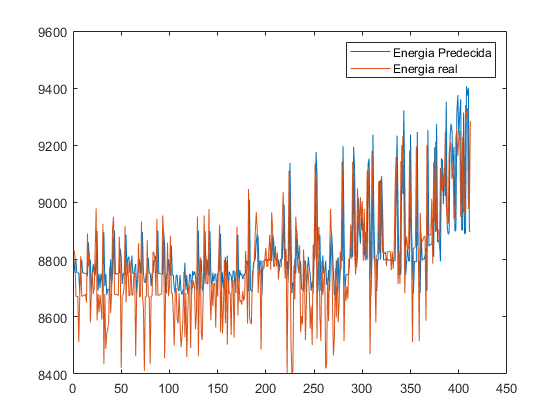

Prediction_DIA=trainedModel_POTENCIA_DIA_85.predictFcn(Data_val_3(:,1));
figure
plot(Prediction_DIA);
hold on
plot(Data_val_3(:,2));
legend('Energia Predecida','Energia real');

% E = fBar_RmseMseMae(Prediction_hora,Data_val_3(:,2));
rmse = sqrt(immse(Prediction_DIA,Data_val_3(:,2)))

rmse = 173.4992

% porcentaje = valor rmse *100 / valor promedio de consumo
porcentaje_error_1_DIA = (rmse * 100)/max(Data_val_3(:,2))

porcentaje_error_1_DIA = 1.8575

porcentaje_exactitud=100-porcentaje_error_1_DIA

porcentaje_exactitud = 98.1425

porcentaje_error_1_DIA = (rmse * 100)/mean(Data_val_3(:,2))

porcentaje_error_1_DIA = 1.9750

% [rmse,mse,r2] = fBar_RmseMseR2(Prediction_dia,Data_val_3(:,2))
% coeficiente de determinacion
r2=fR2(Prediction_DIA,Data_val_3(:,2))

r2 = 0.1498

porcentaje_similitud=1-r2

porcentaje_similitud = 0.8502

% Suma de los cuadrados de la regresión
SSR = sum((Prediction_DIA - mean(Data_val_3(:,2))).^2);  
% Suma total de los cuadrados
SST = sum((Data_val_3(:,2) - mean(Data_val_3(:,2))).^2);  
R2=1-SSR/SST

R2 = 0.3362

ex=1-R2

ex = 0.6638

# Validacion de modelo de mes

[trainedModel_POTENCIA_MES_70_F, validationRMSE_POTENCIA_MES_70_F] = trainRegressionModel_POTENCIA_MES_70_F(Data_train_4)

trainedModel_POTENCIA_MES_70_F = struct with fields:
       predictFcn: @(x)svmPredictFcn(predictorExtractionFcn(x))
    RegressionSVM: [1×1 RegressionSVM]
            About: 'This struct is a trained model exported from Regression Learner R2018a.'
     HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 1 columns because this model was trained using 1 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE_POTENCIA_MES_70_F = 139.9772

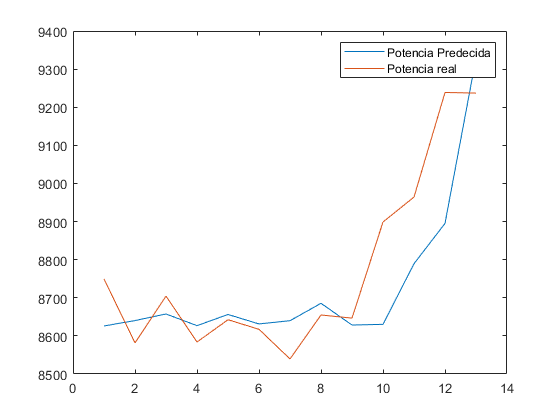

Prediction_MES=trainedModel_POTENCIA_MES_70_F.predictFcn(Data_val_4(:,1));
figure
plot(Prediction_MES);
hold on
plot(Data_val_4(:,2));
legend('Potencia Predecida','Potencia real');

% E = fBar_RmseMseMae(Prediction_hora,Data_val_3(:,2));
rmse = sqrt(immse(Prediction_MES,Data_val_4(:,2)))

rmse = 142.4071

% porcentaje = valor rmse *100 / valor promedio de consumo
porcentaje_error_1_MES = (rmse * 100)/max(Data_val_4(:,2))

porcentaje_error_1_MES = 1.5414

porcentaje_exactitud=100-porcentaje_error_1_MES

porcentaje_exactitud = 98.4586

porcentaje_error_1_MES = (rmse * 100)/mean(Data_val_4(:,2))

porcentaje_error_1_MES = 1.6231

% [rmse,mse,r2] = fBar_RmseMseR2(Prediction_dia,Data_val_3(:,2))
% coeficiente de determinacion
r2=fR2(Prediction_MES,Data_val_4(:,2))

r2 = 0.6169

porcentaje_similitud=1-r2

porcentaje_similitud = 0.3831

% Suma de los cuadrados de la regresión
SSR = sum((Prediction_MES - mean(Data_val_4(:,2))).^2);  
% Suma total de los cuadrados
SST = sum((Data_val_4(:,2) - mean(Data_val_4(:,2))).^2);  
R2=1-SSR/SST

R2 = 0.2741

ex=1-R2

ex = 0.7259

# Calculo de MAPE en 1 mes

% Predicciones del modelo (reemplaza estos valores con las predicciones de tu modelo)
predicciones = [Prediction_MES];

% Valores reales (reemplaza estos valores con los valores reales correspondientes)
valores_reales = [Data_val_4(:,2)];

% Cálculo del error absoluto
error_absoluto = abs(valores_reales - predicciones);

% Cálculo del porcentaje de error absoluto
porcentaje_error_absoluto = (error_absoluto ./ abs(valores_reales)) * 100;

% Cálculo del MAPE (promedio de los porcentajes de error absoluto)
mape = mean(porcentaje_error_absoluto);

% Imprimir el resultado del MAPE
fprintf('El Error de Predicción MAPE es: %.2f%%\n',mape);

El Error de Predicción MAPE es: 1.14%


# Calculo de MAE en 1 mes

% Predicciones del modelo (reemplaza estos valores con las predicciones de tu modelo)
predicciones = [Prediction_MES];

% Valores reales (reemplaza estos valores con los valores reales correspondientes)
valores_reales = [Data_val_4(:,2)];

% Cálculo del error absoluto
error_absoluto = abs(valores_reales - predicciones);

% Cálculo del MAE (promedio de los errores absolutos)
mae = mean(error_absoluto);

% Imprimir el resultado del MAE
fprintf('El MAE (Error Absoluto Medio) es: %.2f\n',mae);

El MAE (Error Absoluto Medio) es: 102.12


# Calculo de MSE en 1 mes

% Predicciones del modelo (reemplaza estos valores con las predicciones de tu modelo)
predicciones = [Prediction_MES];

% Valores reales (reemplaza estos valores con los valores reales correspondientes)
valores_reales = [Data_val_4(:,2)];

% Cálculo del error cuadrático
error_cuadratico = (valores_reales - predicciones).^2;

% Cálculo del MSE (promedio de los errores cuadráticos)
mse = mean(error_cuadratico);

% Imprimir el resultado del MSE
fprintf('El MSE (Mean Squared Error) es: %.2f\n',mse);

El MSE (Mean Squared Error) es: 20279.78


# Validacion de modelo de 3 mes

[trainedModel_SVM_3_meses, validationRMSE_SVM_3_meses] = trainRegressionModel_SVM_3_meses(Data_train_5)

Undefined function or variable 'Data_train_5'.

Prediction_3_meses=trainedModel_SVM_3_meses.predictFcn(Data_val_5(:,1));
figure
plot(Prediction_3_meses);
hold on
plot(Data_val_5(:,2));
legend('Potencia Predecida','Potencia real');
% E = fBar_RmseMseMae(Prediction_hora,Data_val_3(:,2));
rmse = sqrt(immse(Prediction_3_meses,Data_val_5(:,2)))

# Validacion de modelo de 6 mes

[trainedModel_SLR_6_meses, validationRMSE_SLR_6_meses] = trainRegressionModel_SLR_6_meses(Data_train_6)
Prediction_6_meses=trainedModel_SLR_6_meses.predictFcn(Data_val_6(:,1));
figure
plot(Prediction_6_meses);
hold on
plot(Data_val_6(:,2));
legend('Potencia Predecida','Potencia real');
% E = fBar_RmseMseMae(Prediction_hora,Data_val_3(:,2));
rmse = sqrt(immse(Prediction_6_meses,Data_val_6(:,2)))

# Calculo de energia

% Crear una tabla de ejemplo
data_energy = table([10; 20; 30], [5; 4; 3], 'VariableNames', {'A', 'B'});

% Dividir los valores de la tabla en una nueva tabla
newData = splitvars(data);

# Graficar la simulación en plot

entrada=yout(:,1);
salida=yout(:,2);
figure ()
plot(entrada);
hold on
plot(salida);
grid on
xlabel('Tiempo (S)');
ylabel('Potencia');
title('Grafica de simulación');
legend('entrada','salida');

# 2- Every 60 samples the value of 1 minute is averaged

win=6*24;% 1 minute
%It takes time to iterate the number of samples / time window.
allDataMean = Data_MeanWin(allData,win);
%save(fullfile(datapath,'allData.mat'),'allData');%No es posible para datos
%mayores a 2GB
save(fullfile(datapath,'allDataMean.mat'),'allDataMean');
clear allData win

# 3- Plot Raw Data (Dataset)

figure
plot(allDataMean);title('Raw Data');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor',...
    'ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)','GPU Consumption (%)'...
    ,'GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

# [4] - Feature Extraction (Please set TimeStep per time window)

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
allDataMean = load(fullfile(datapath,'allDataMean.mat'));%List All CSV files
allDataMean=allDataMean.allDataMean;
allDataMean=allDataMean(1:round(size(allDataMean,1)*.84),:);%Eliminates the final 16% with noise (.93)
figure
plot(allDataMean);title('Graph of 93% of raw data');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');
AEds = datastats(allDataMean(:,6))%Active Energy Statistics with cumulative values
%<----------------------------- Please select only one TimeStep
n = input(['Please select only one number (minute = 1,' ...
    ' hour = 2, day = 3, week = 4, month = 5),: ']);

switch n
    case 1
        TimeStep =1;% one minute
        disp('TimeStep selected is minute')
    case 2
        TimeStep =60;% one hour in minutes
        disp('TimeStep selected is hour')
    case 3
        TimeStep =1440;% one day in minutes (ok)
        disp('TimeStep selected is day')
    case 4
        TimeStep =10080;% one week in minutes (ok)
        disp('TimeStep selected is week')
    case 5
        TimeStep =40320;% one month in minutes (only 8 monthss) (ok)
        disp('TimeStep selected is month')
    otherwise
        disp('other value')
end

figure; DataFeatures = frms_features_v2(allDataMean,TimeStep);
plot(DataFeatures);title('RMS Features by TimeStep (Accumulated Active Energy)');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');
figure; subplot(3,1,1)
plot(DataFeatures(:,9:11));title('Feature CPU Data');xlabel('samples');ylabel('value');
legend('CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)');
subplot(3,1,2)
plot(DataFeatures(:,12:14));title('Feature GPU Data');xlabel('samples');ylabel('value');
legend('GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)');
subplot(3,1,3)
plot(DataFeatures(:,15:16));title('Feature RAM Data');xlabel('samples');ylabel('value');
legend('RAM Consumption (%)','RAM Power Consumption (%)');
figure; DataFeatures(:,6)= fmax_features(allDataMean(:,6),TimeStep);
DataFeatures(:,6)=hampel(DataFeatures(:,6));
plot(DataFeatures);title('RMS Features by TimeStep (Active Energy without accumulation)');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');
AEds = datastats(DataFeatures(:,6))%Active Energy (KWh), without accumulation (separated by time window)
figure; bar(DataFeatures(:,6));title('Active Energy without accumulation (separated by time window)');xlabel('samples');ylabel('value');
legend('Active Energy (KWh)');
clear allDataMean TimeStep

# 5- Statital Features Information

%WeekDay','Voltage (V)'
[wds,vds] = datastats(DataFeatures(:,1),DataFeatures(:,2))
%'Current (A)','Active Power (W)'
[cds,pds] = datastats(DataFeatures(:,3),DataFeatures(:,4))
%'Frecuency (Hz)','Active Energy (KWh)'
[fds,eds] = datastats(DataFeatures(:,5),DataFeatures(:,6))
%'Power Factor','ESP32 Temperature (°C)'
[pfds,tds] = datastats(DataFeatures(:,7),DataFeatures(:,8))
%'CPU Consumption (%)','CPU Power Consumption (%)'
[cpuds,cpupds] = datastats(DataFeatures(:,9),DataFeatures(:,10))
%'CPU Temperature (%)',%'GPU Consumption (%)'
[cputds,gpuds] = datastats(DataFeatures(:,11),DataFeatures(:,12))
%'GPU Power Consumption (%)','GPU Temperature (%)'
[gpupds,gputds] = datastats(DataFeatures(:,13),DataFeatures(:,14))
%'RAM Consumption (%)','RAM Power Consumption (%)'
[ramds,rampds] = datastats(DataFeatures(:,15),DataFeatures(:,16))
clear wds vds cds pds fds eds pfds tds cpuds cpupds cputds gpuds gpupds gputds ramds rampds

# 6- Feature Normalization and Plot

allFeatureNorm = fNormalization(DataFeatures);%Normalization
figure; plot(allFeatureNorm);title('Normalized Data (separated by time window)');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');
figure; bar(allFeatureNorm(:,6));title('Normalized data for Active energy consumption');xlabel('samples');ylabel('value');
legend('Active Energy (KWh)');
clear DataFeatures

# 7 - Feature Selection (Please set the maximum correlation value allowed.)

threshold = 0.75;%75<-------Maximum correlation value allowed
% Labels:
FeaturesLabels = {'WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor',...
    'ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)','GPU Consumption (%)'...
    ,'GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)'};
[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(allFeatureNorm,FeaturesLabels,threshold);
LabelsRemove(:)
clear threshold LabelsRemove ans allFeatureNorm FeaturesLabels

# 8 - Regression Learner (Input output Data)

training_size=0.85; %70 Training, 15% Validation
Cell_Active_Energy=strfind(NewFeaturesLabels, 'Active Energy (KWh)');
ind_Active_Energy = find(not(cellfun('isempty',Cell_Active_Energy)));

% ---------------inputs: All previously selected features------------------
input_train=NewDataFeatures(1:round(size(NewDataFeatures,1)*training_size)-1,:);

% ----------------output: Energy in the next time step---------------------
output_train=NewDataFeatures(1+1:round(size(NewDataFeatures,1)*training_size),...
    ind_Active_Energy);%Active Energy index 5
%regressionLearner
clear Cell_Active_Energy Features_labels

# RMSE (Validation): 1 Week [threshold = 0.750;training_size=0.85;]

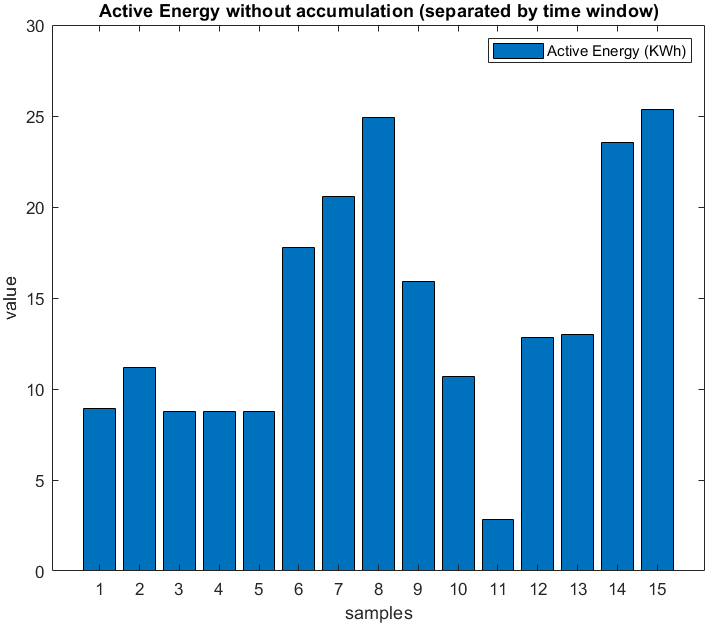

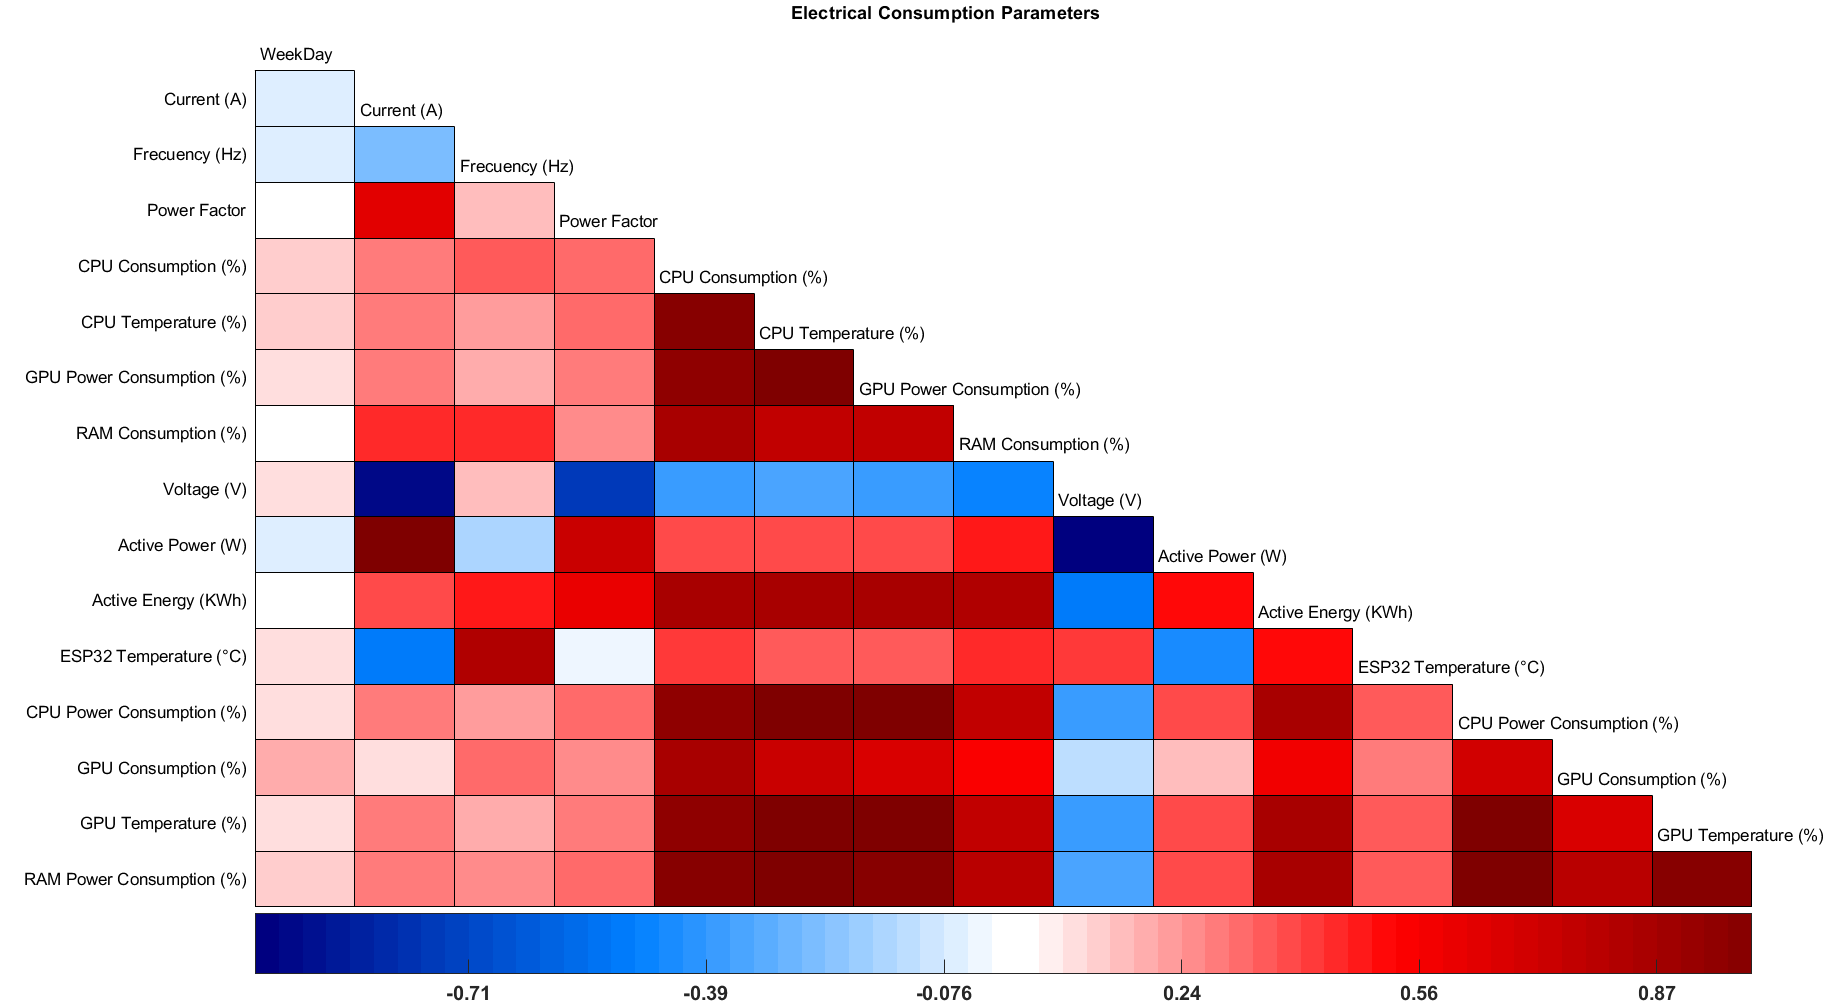

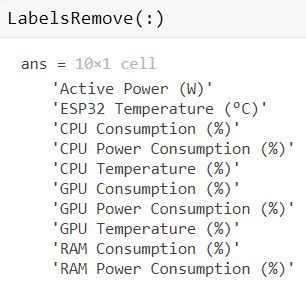

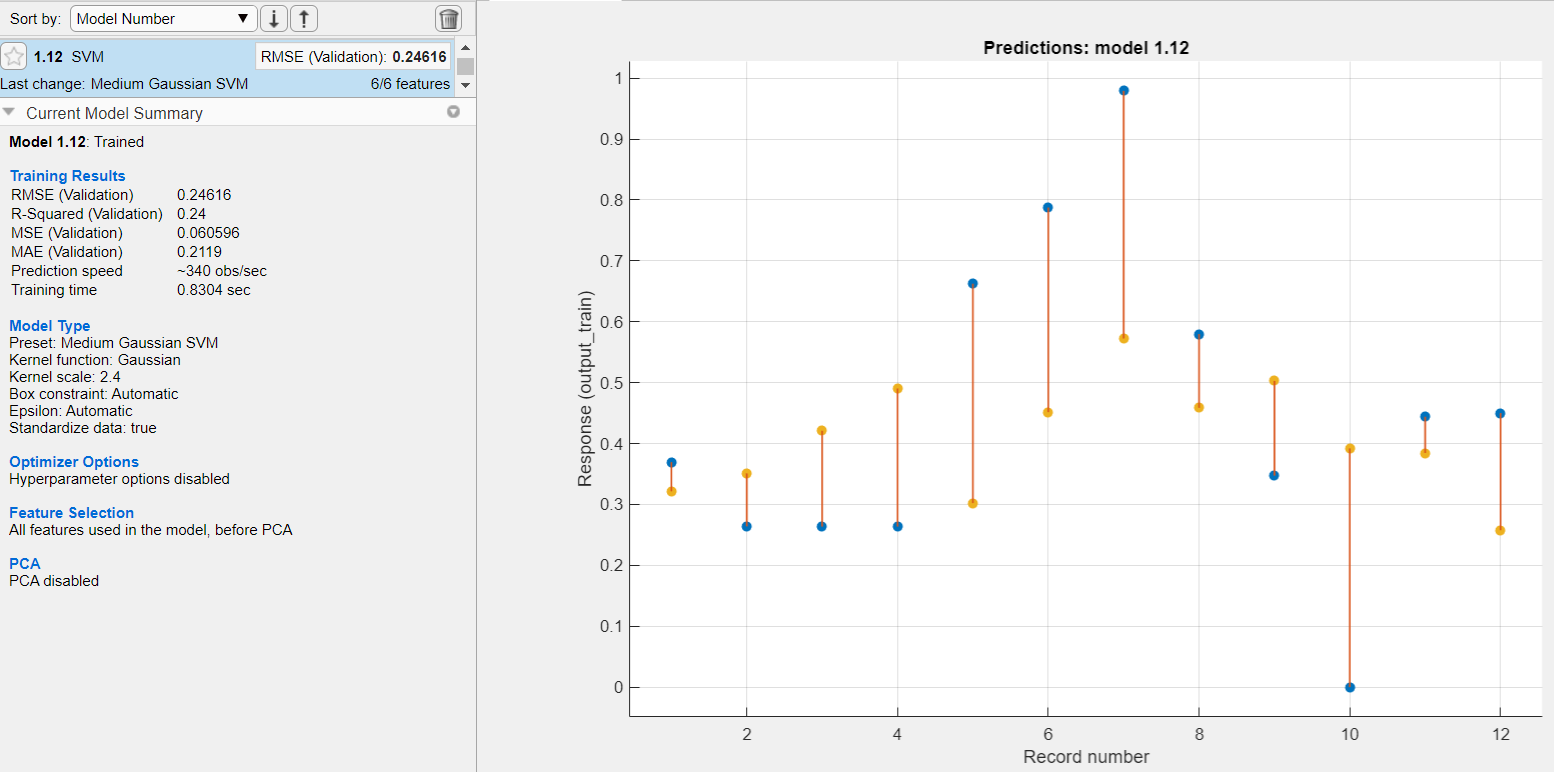

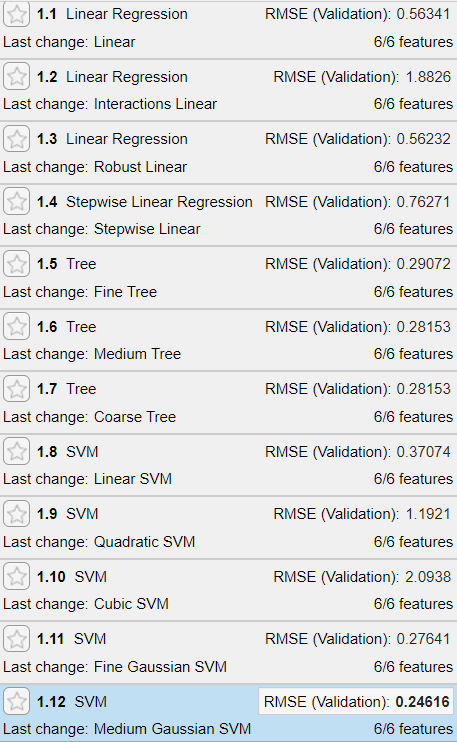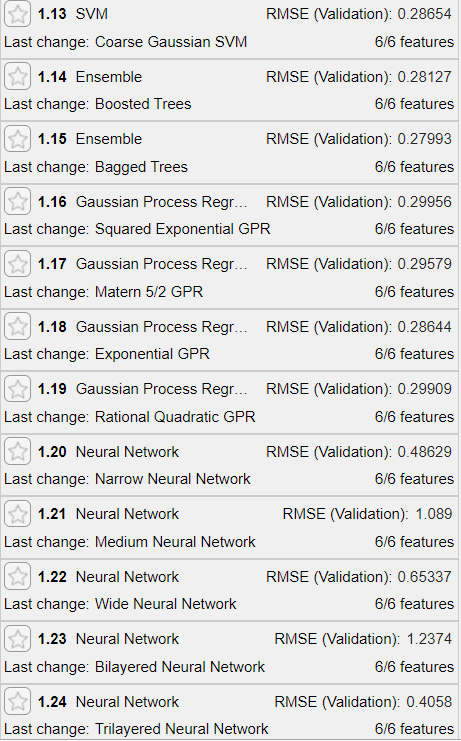

# RMSE (Validation - Filtrado): 1 Week [threshold = 0.750;training_size=0.85;]

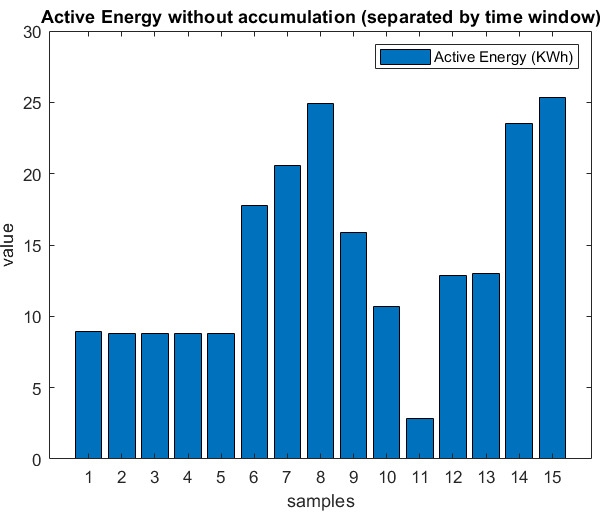

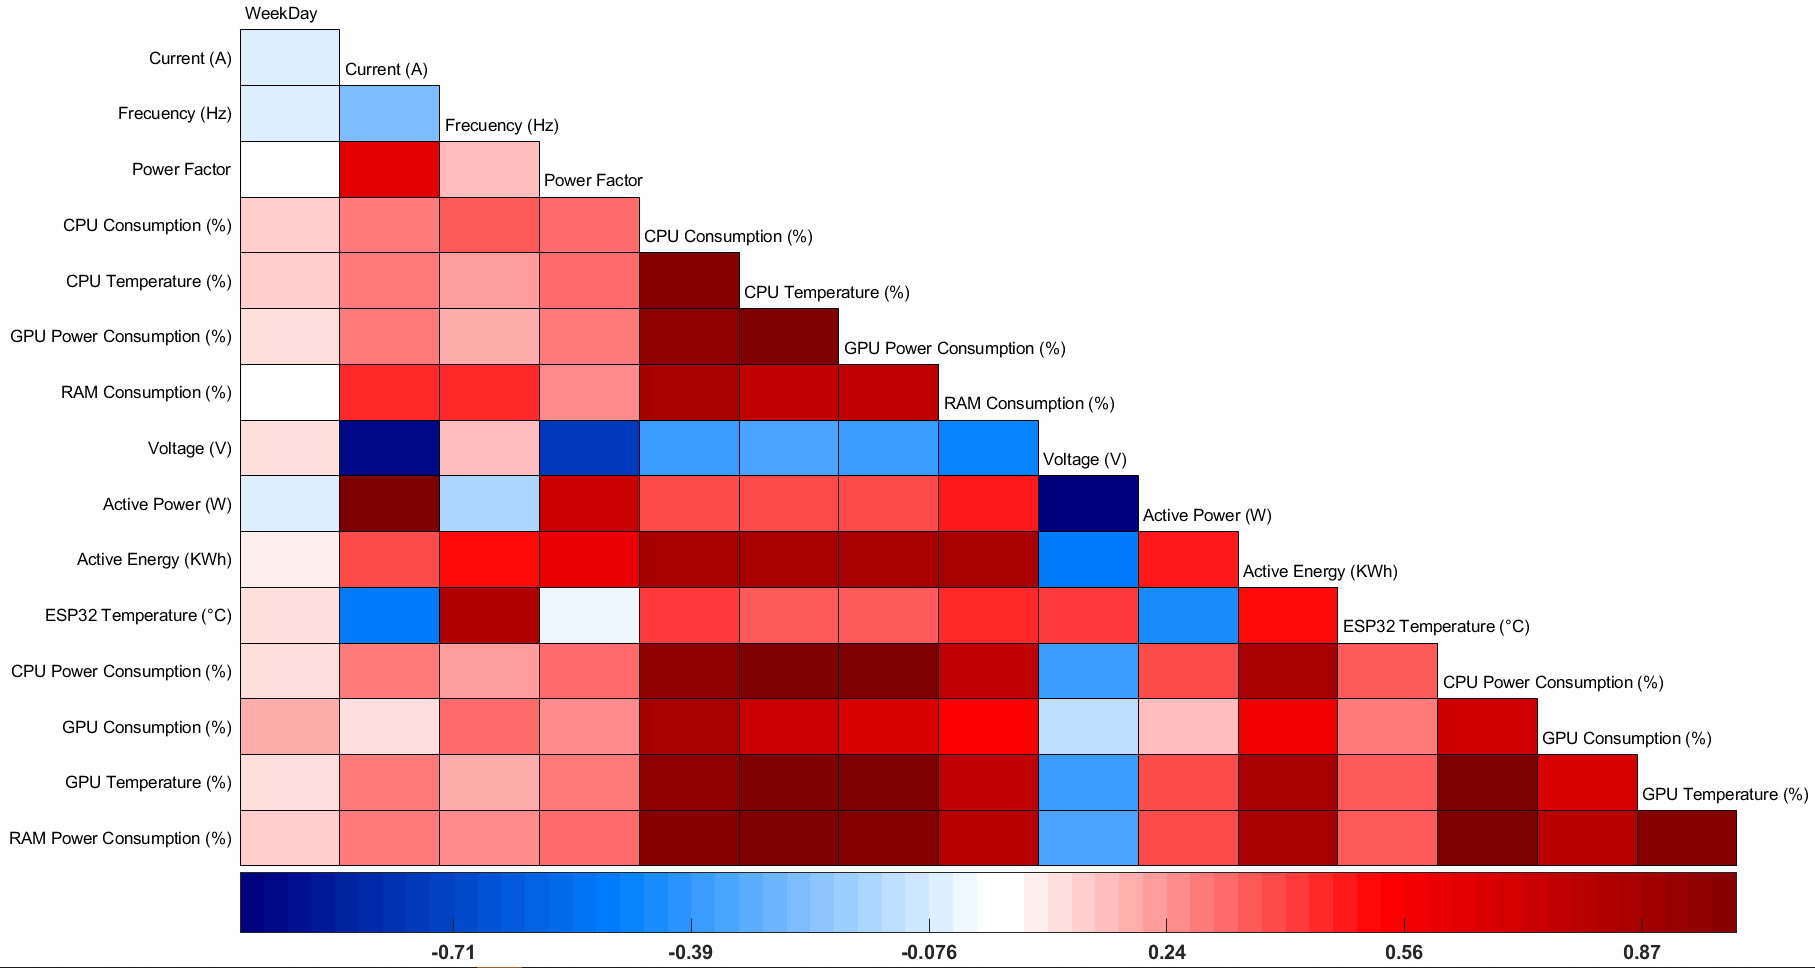

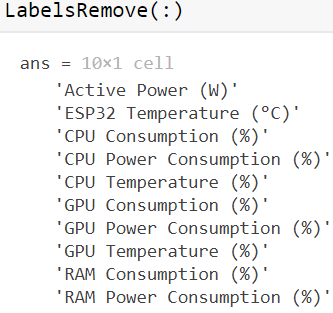

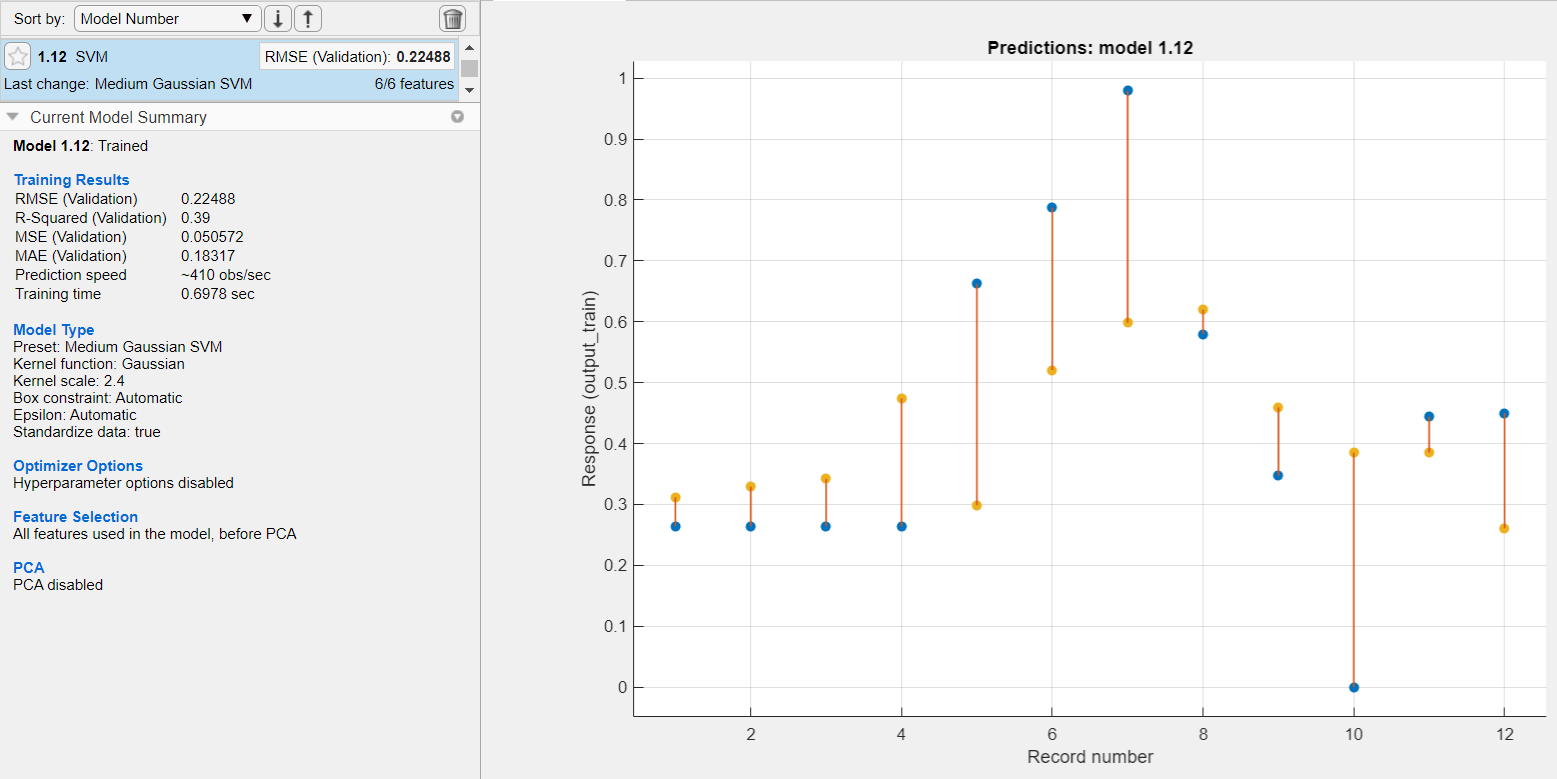

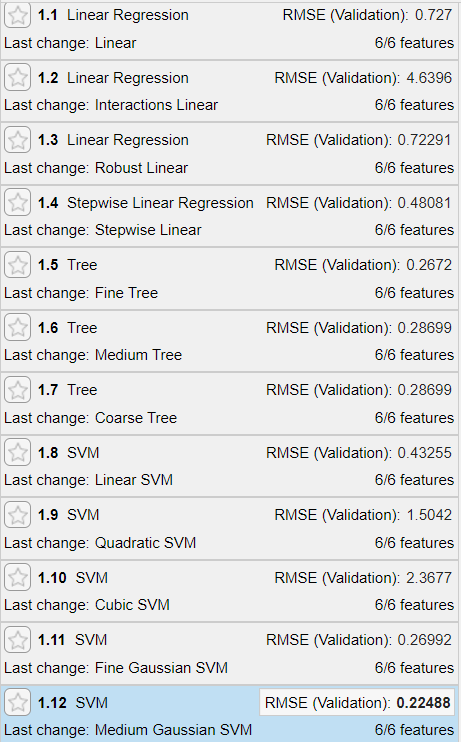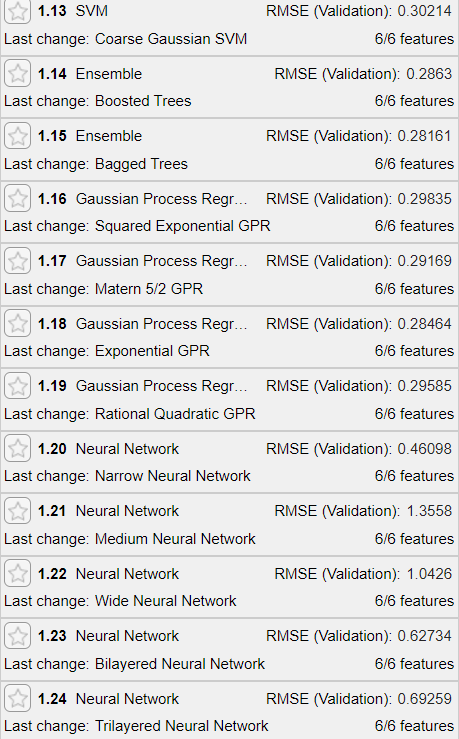

# RMSE (Validation): 1 day [threshold = 0.750;training_size=0.85;]

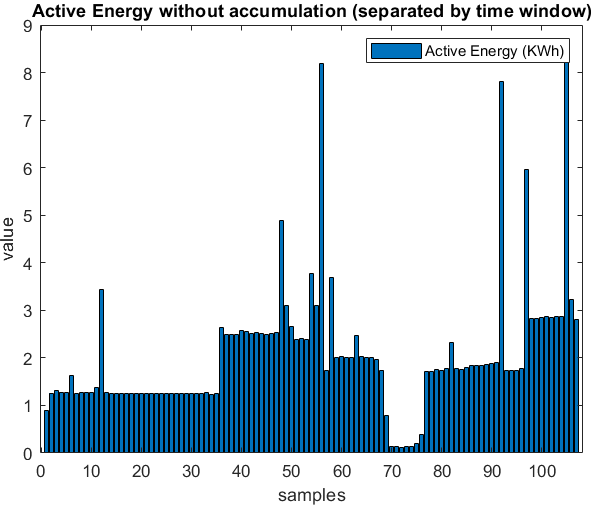

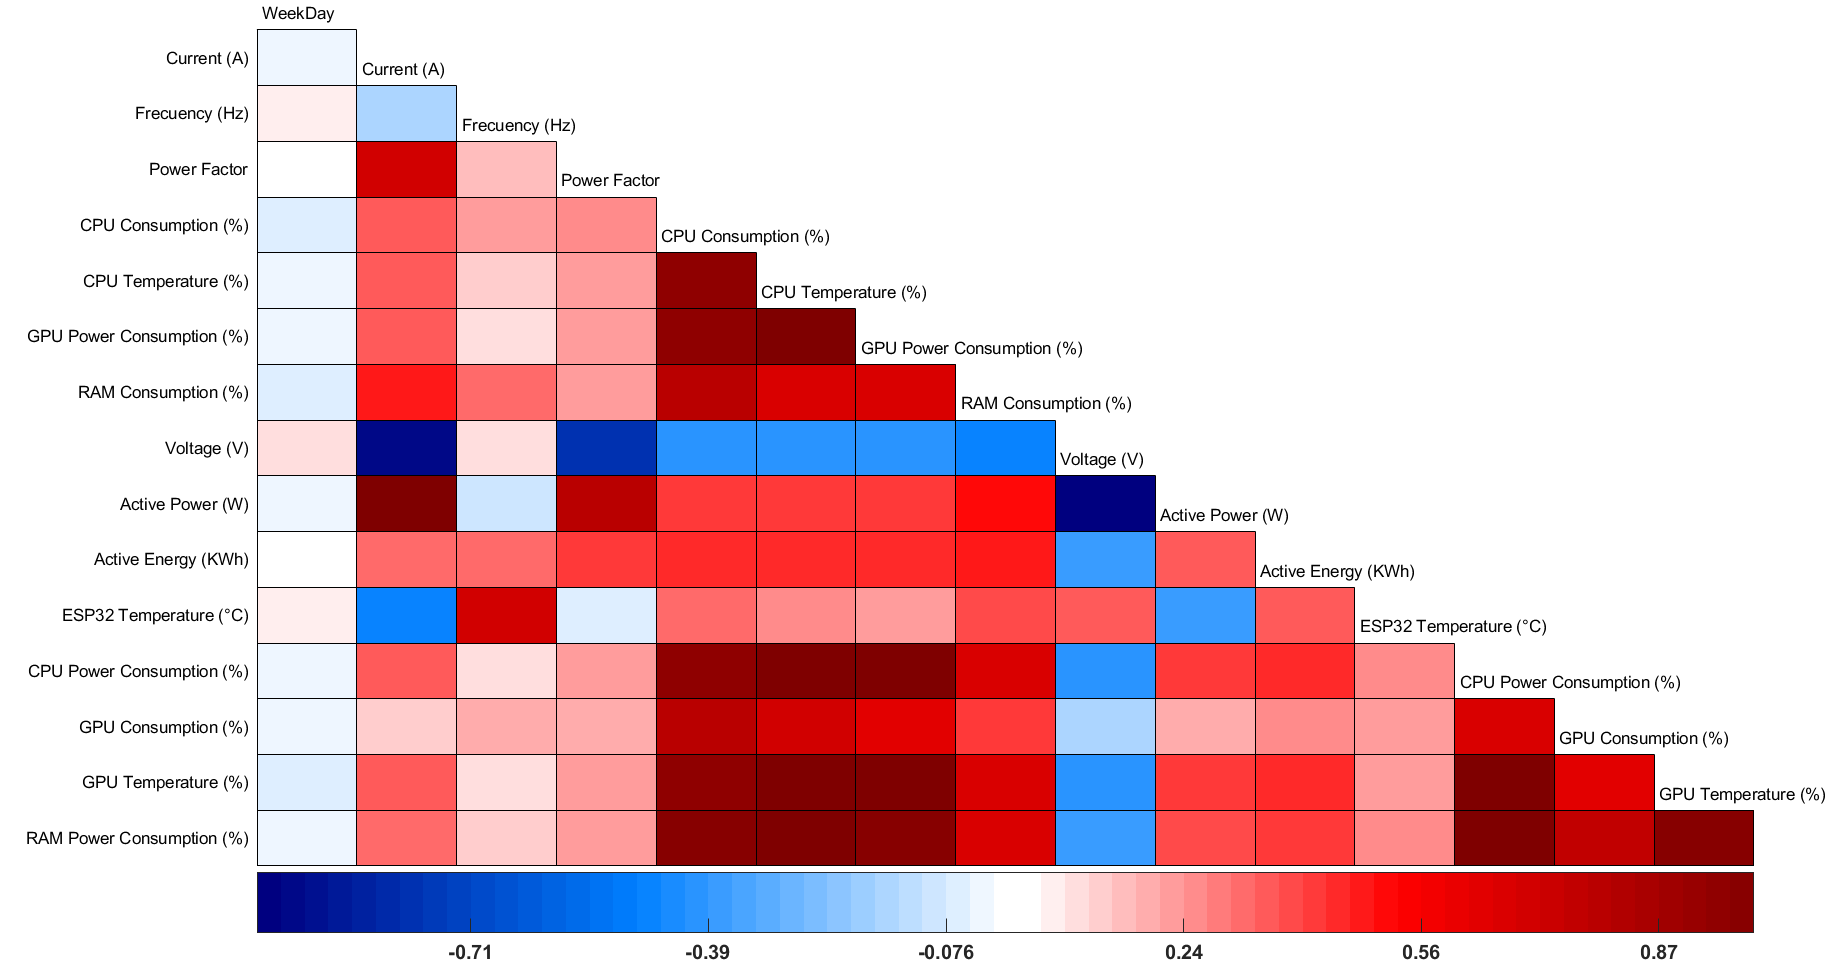

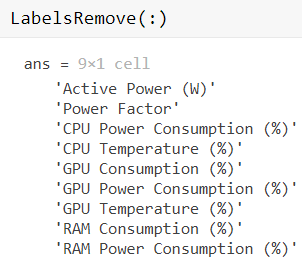

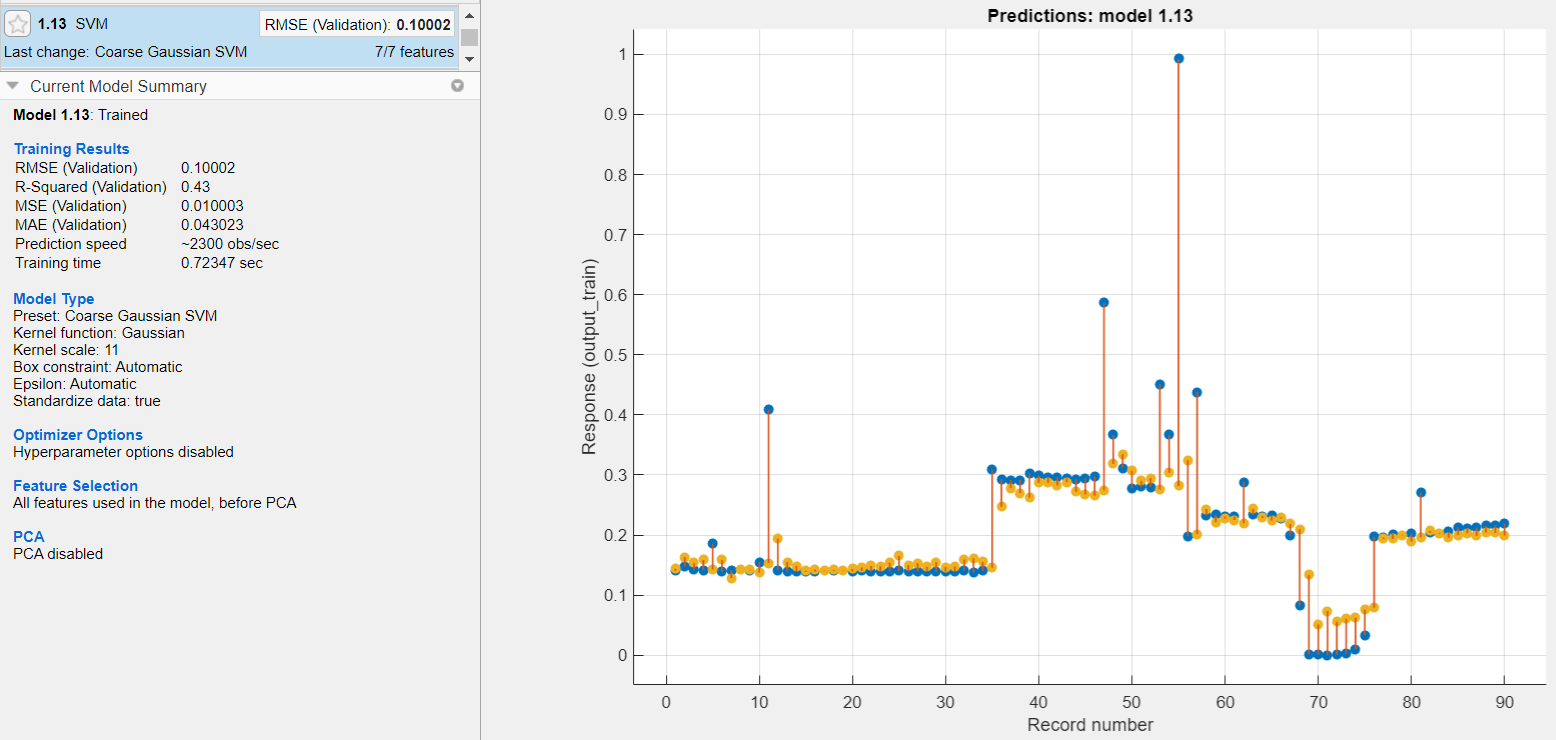

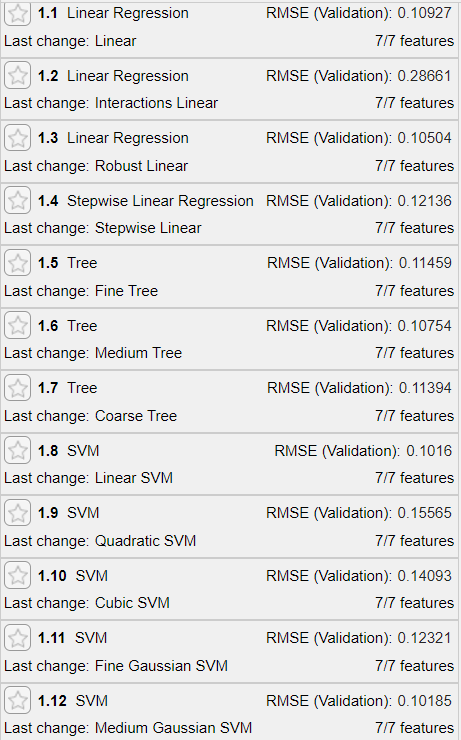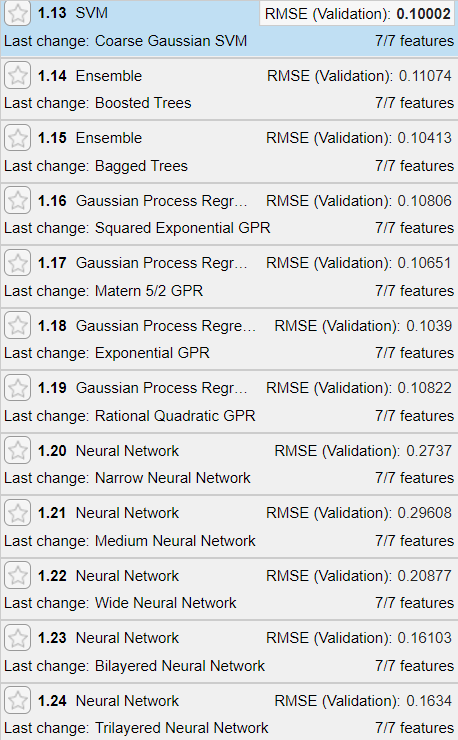

# RMSE (Validation - Filtrado): 1 day [threshold = 0.750;training_size=0.85;]

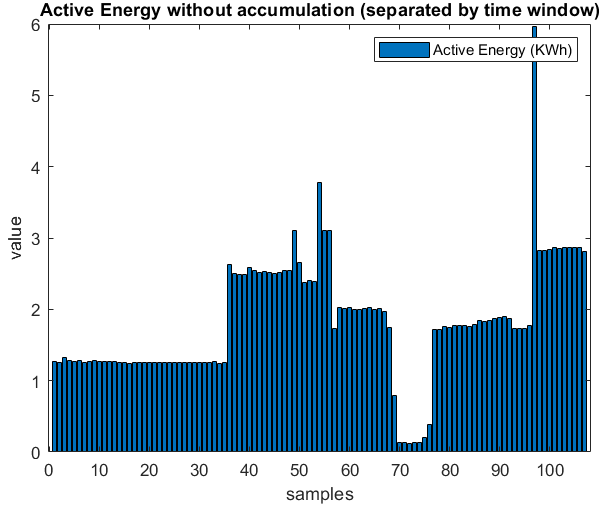

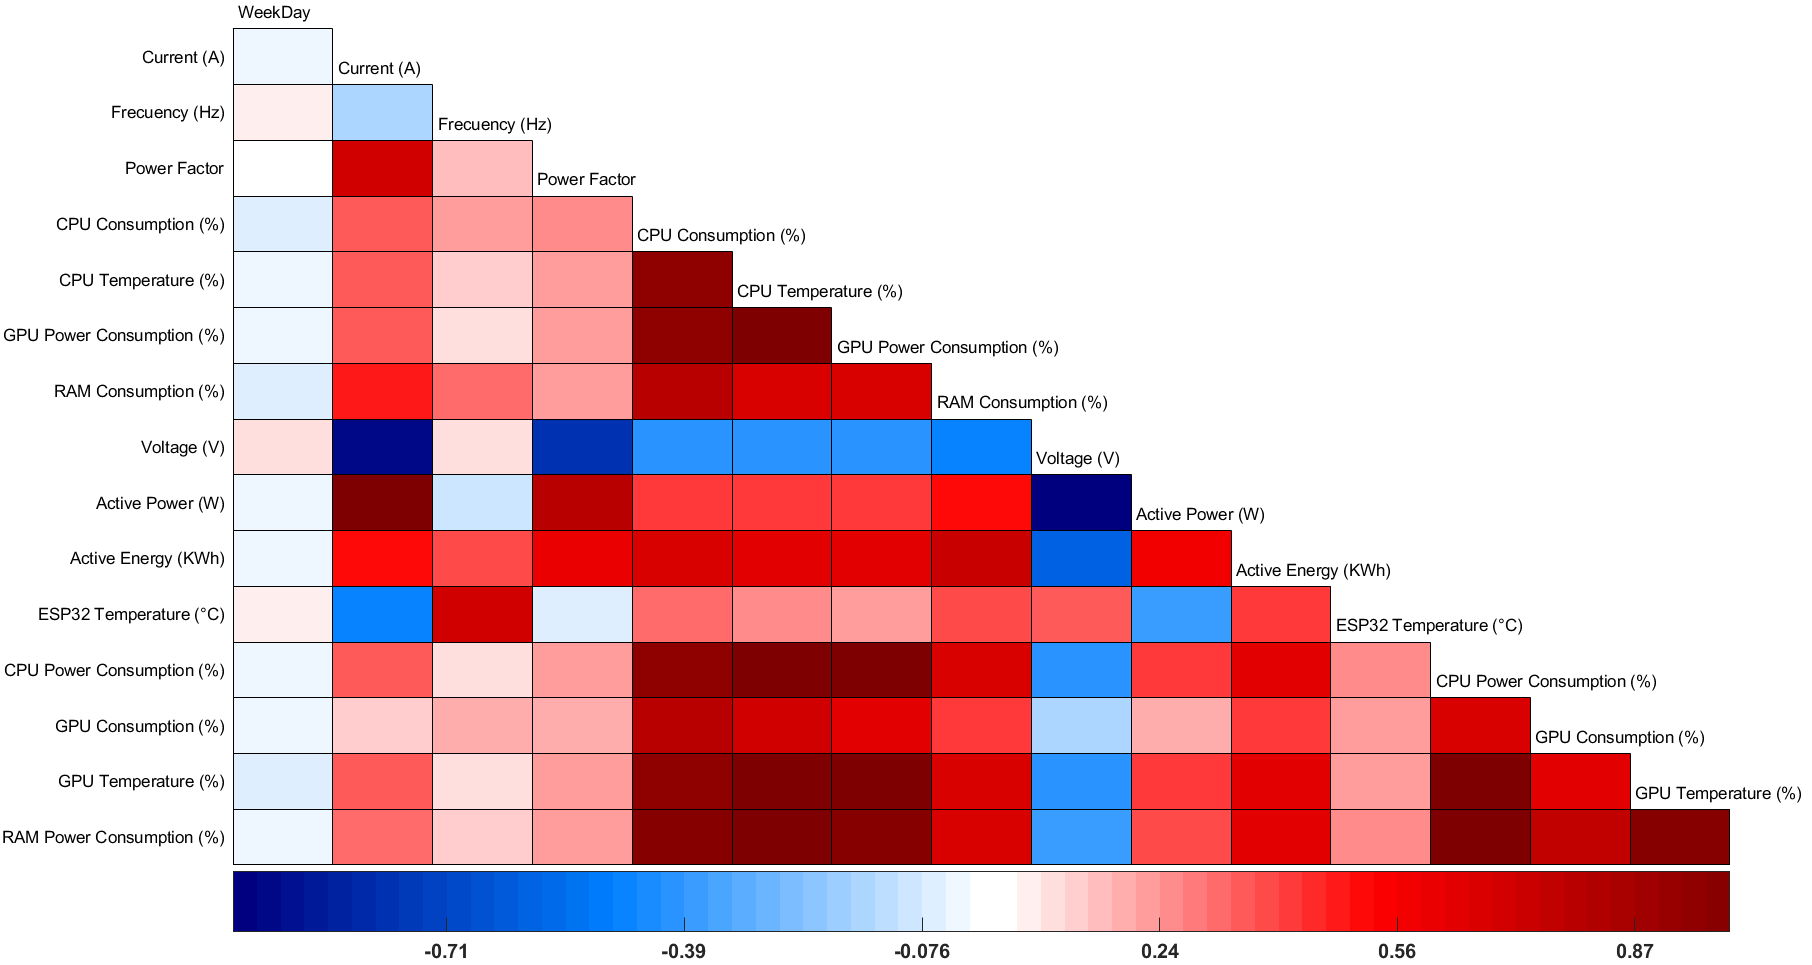

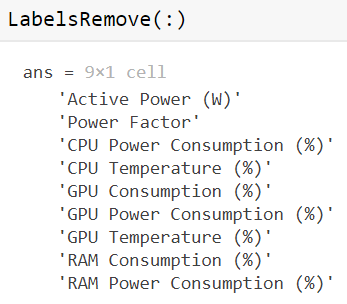

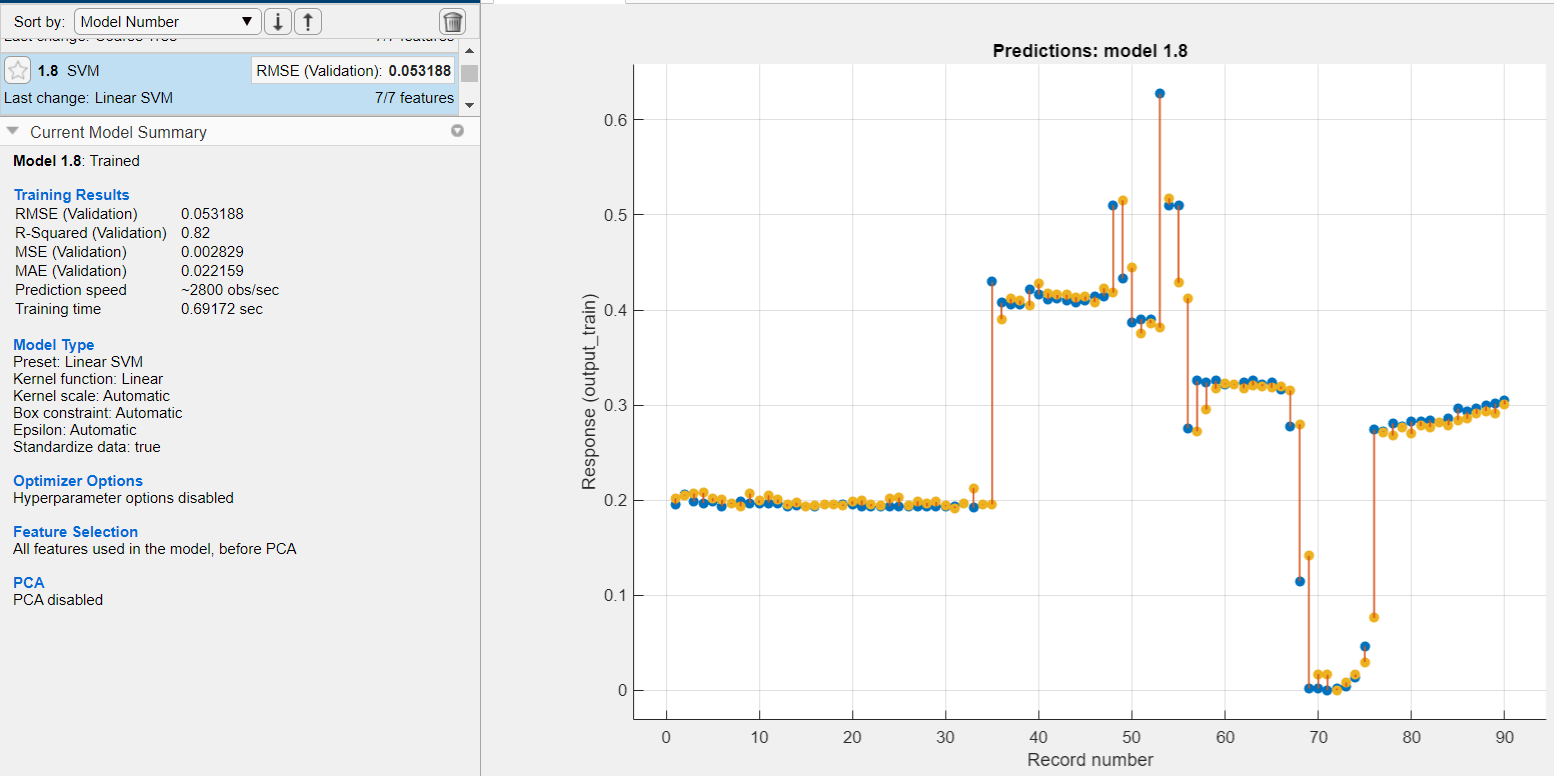

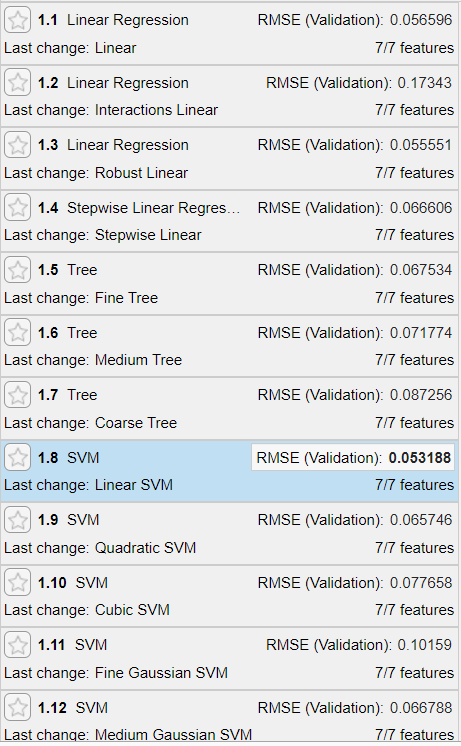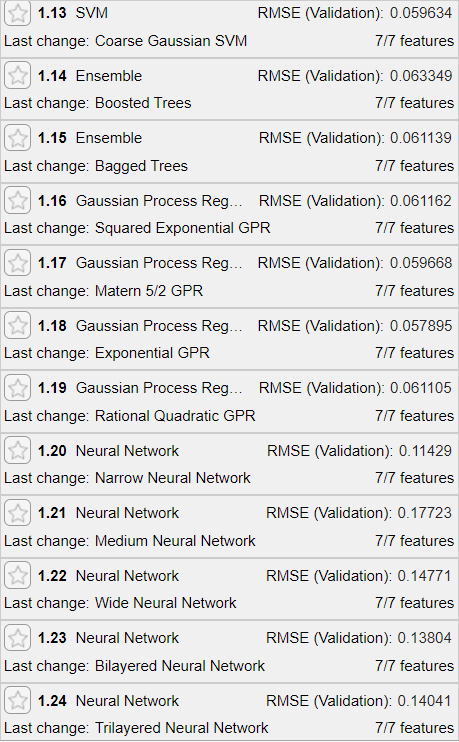

# RMSE (Validation): 1 hour [threshold = 0.750;training_size=0.85;]

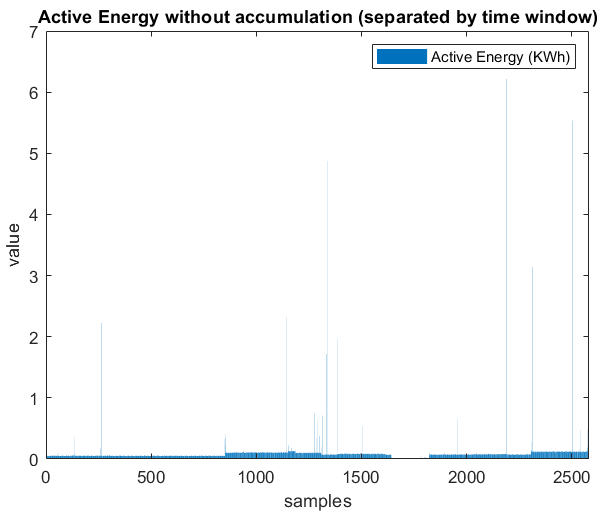

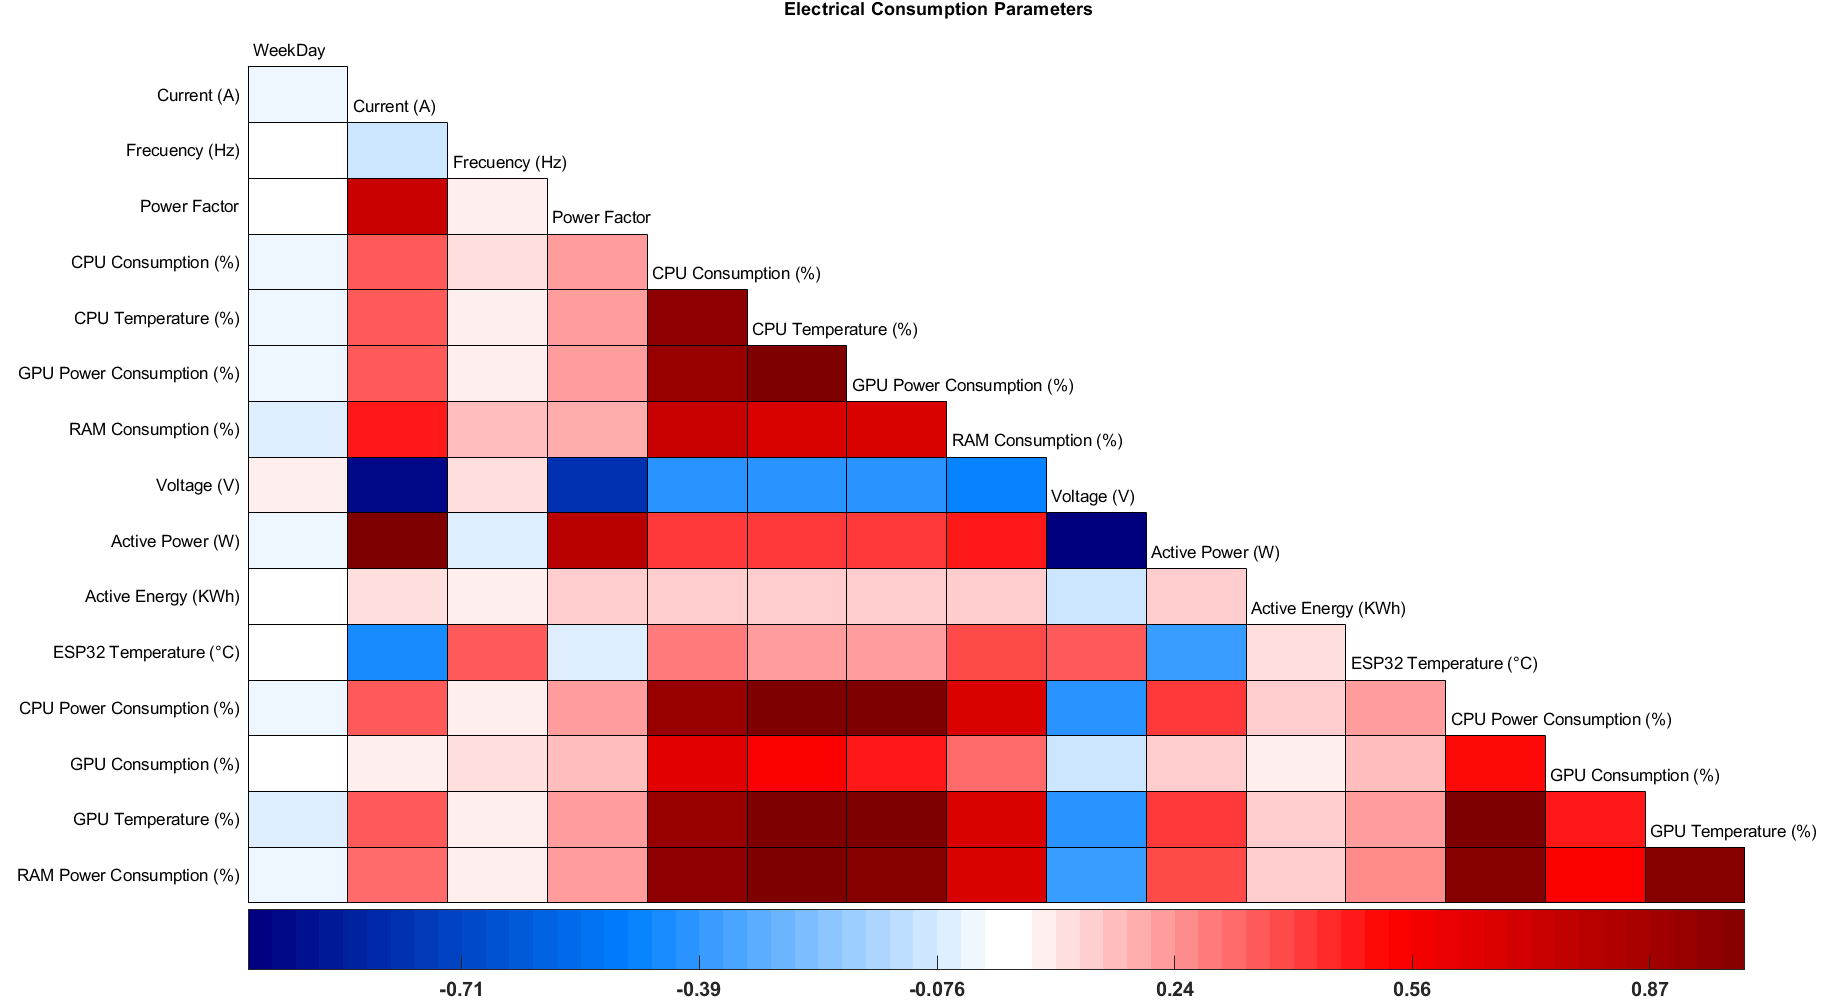

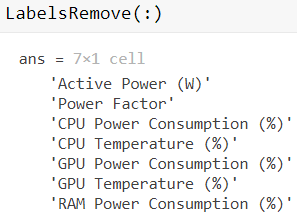

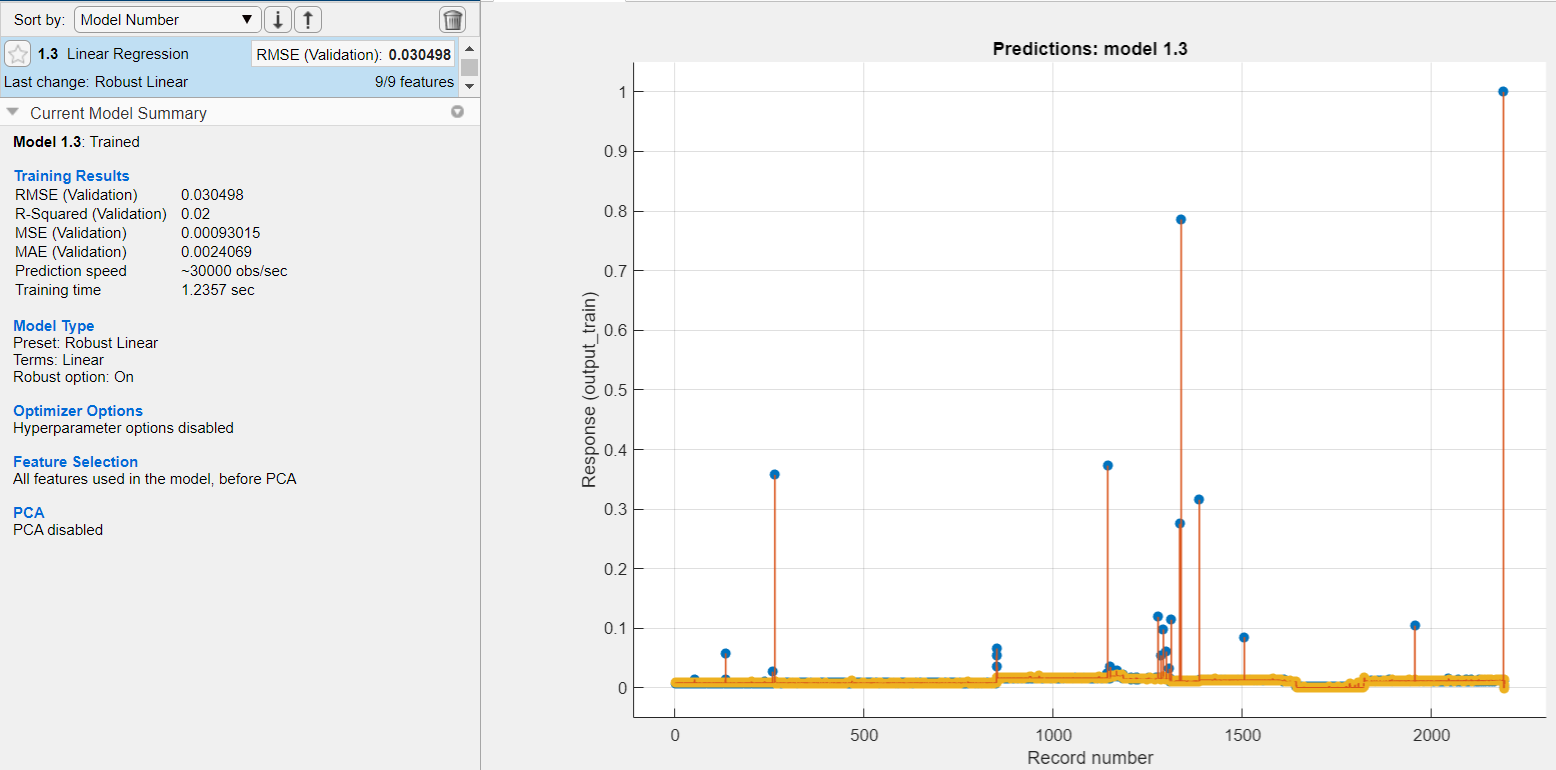

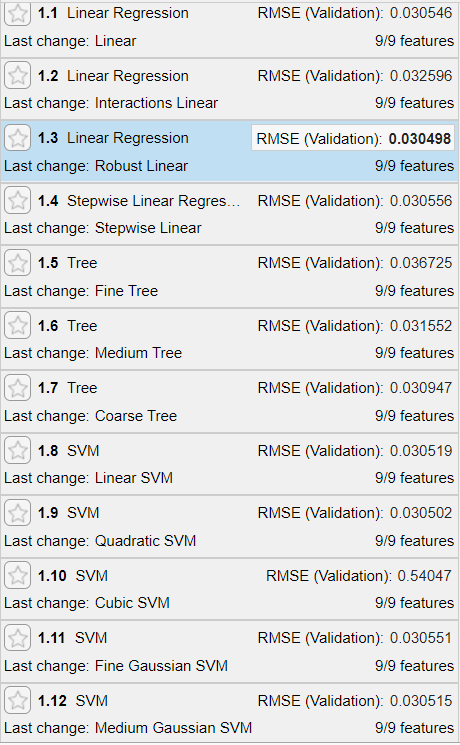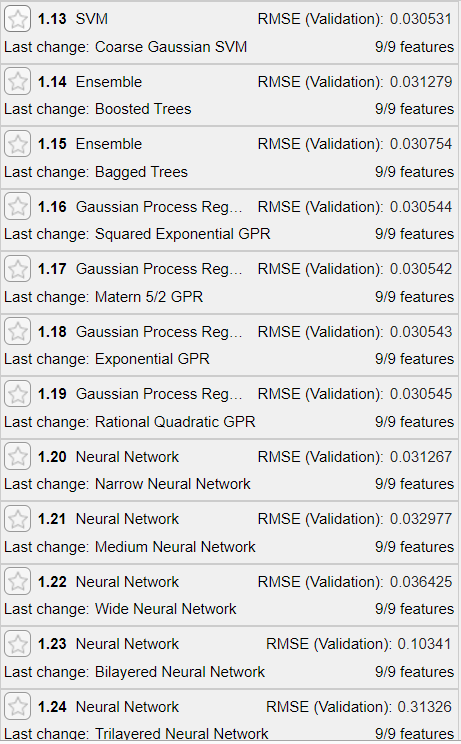

# RMSE (Validation - Filtrado): 1 hour [threshold = 0.750;training_size=0.85;]

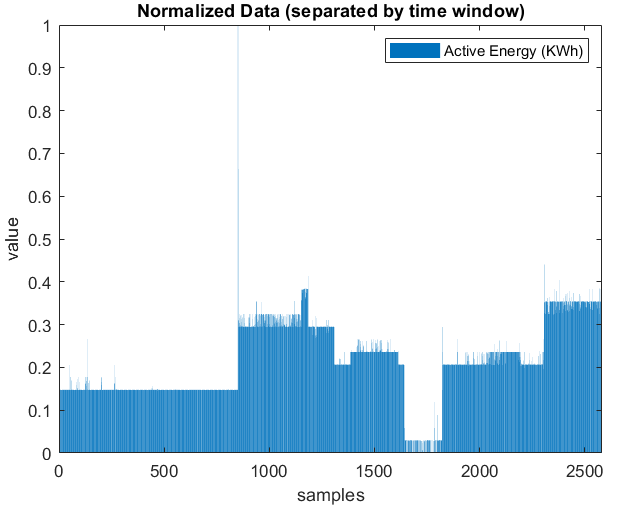

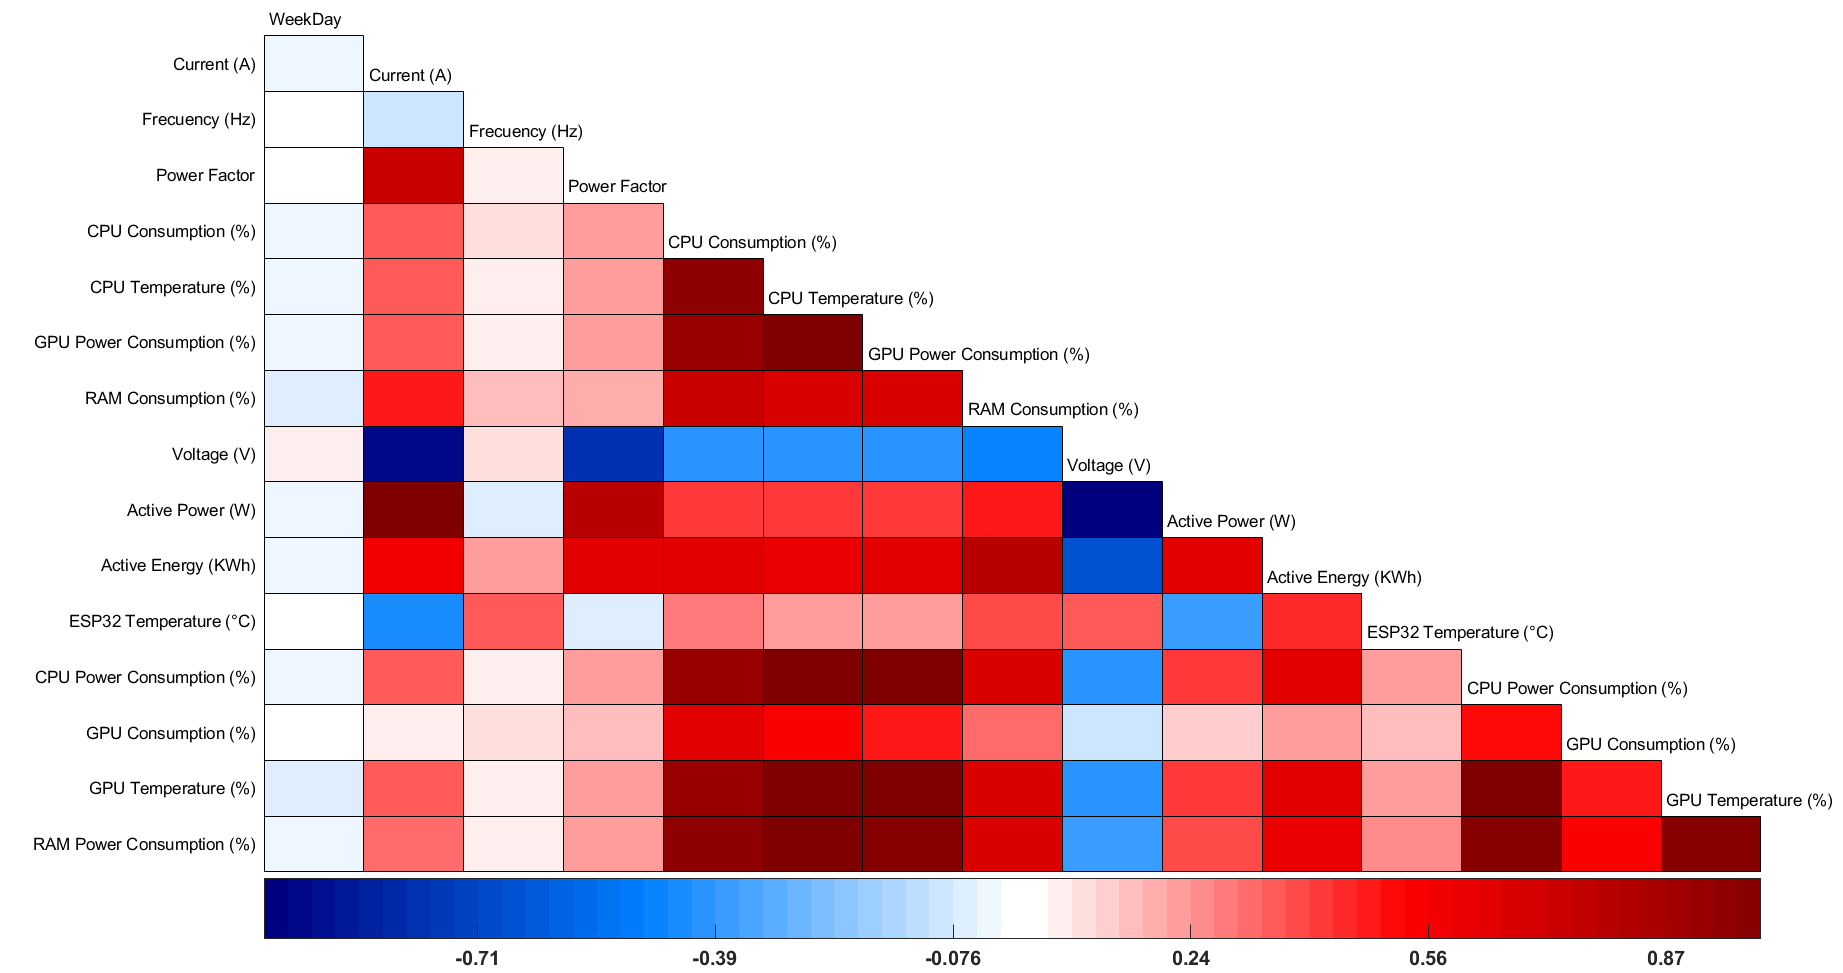

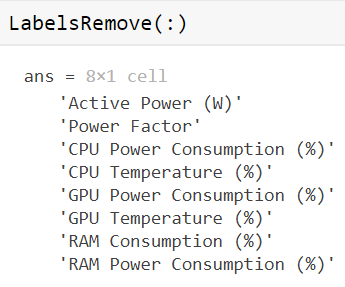

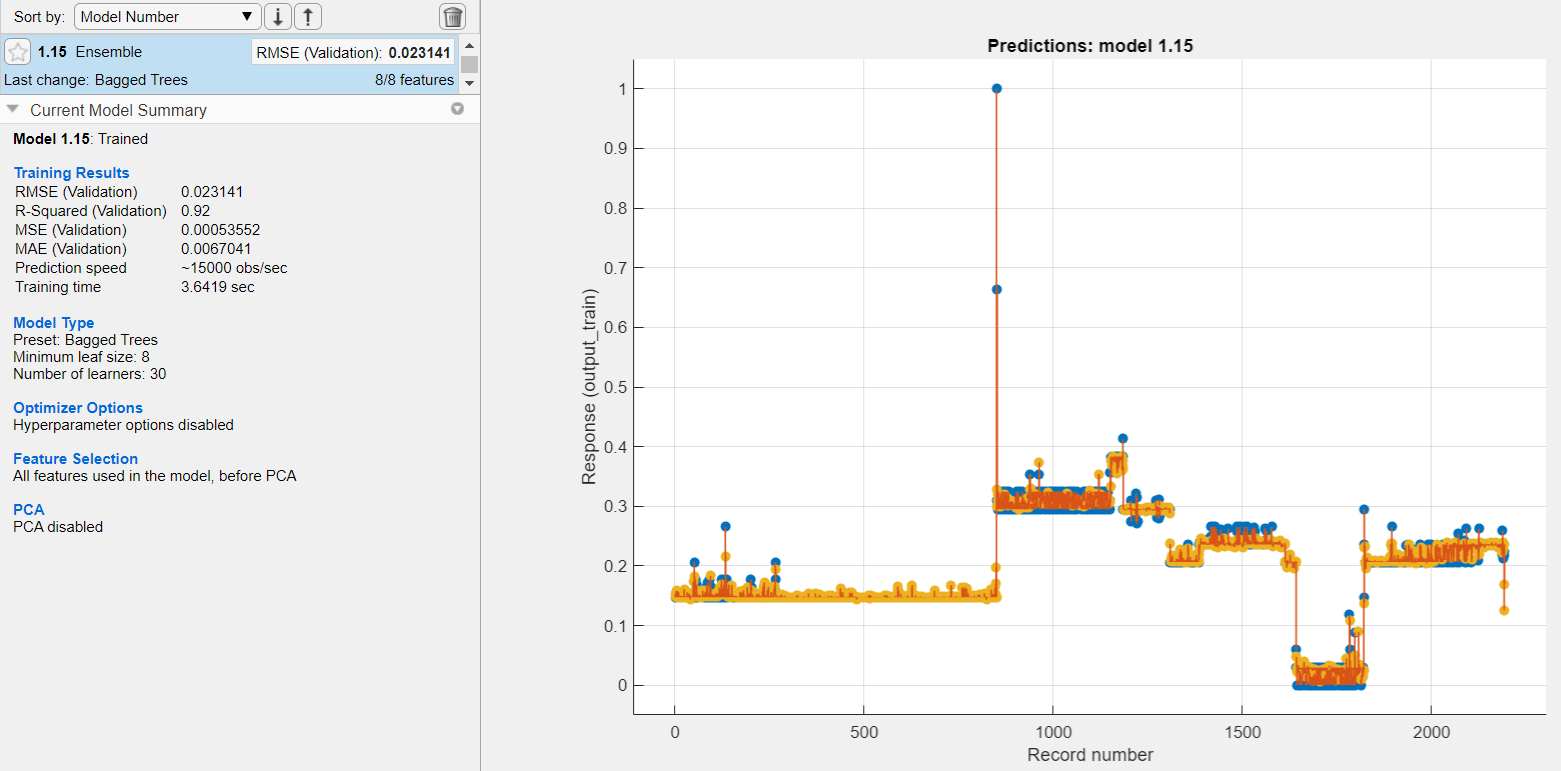

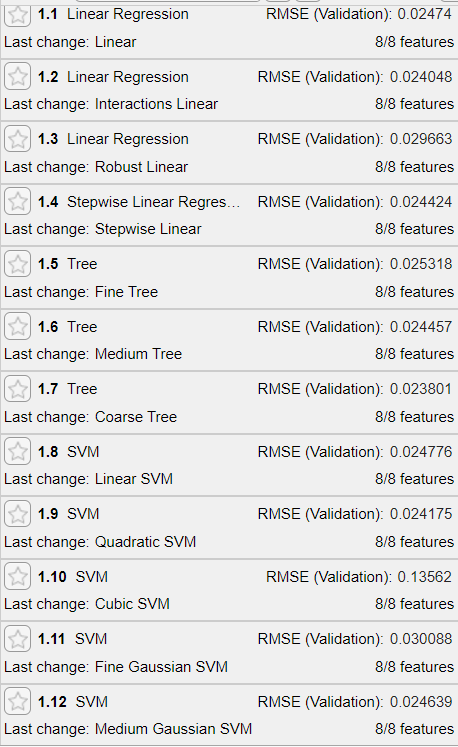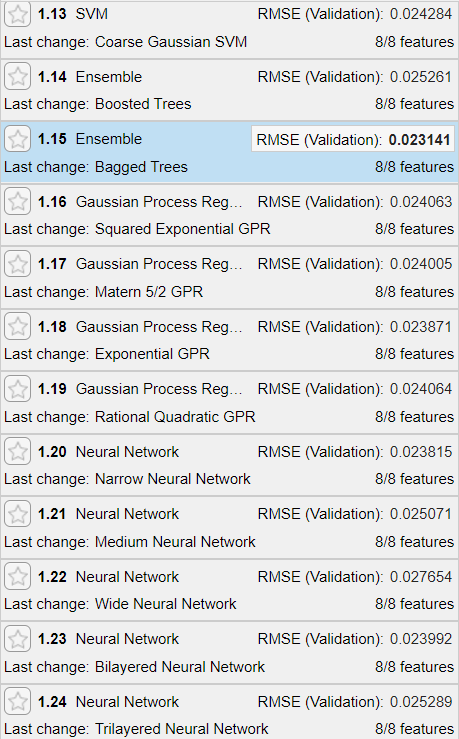

# RMSE (Testing): 1 month [threshold = 0.750;training_size=0.85;]

training_size=0.40;
% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_month, RMSE_month] = trainRegressionModel_month(input_train, output_train);
RMSE_month
estimate_month=model_month.predictFcn(input_val);
estimate_month=fDenormalize(estimate_month,AEds.max,AEds.min);
output_month=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_month,output_month]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 month of prediction');
[rmse_month,mse_month,mae_month]=fBar_RmseMseMae(estimate_month,output_month);
save(fullfile(datapath,'rmse_month.mat'),'rmse_month');
save(fullfile(datapath,'mse_month.mat'),'mse_month');
save(fullfile(datapath,'mae_month.mat'),'mae_month');

%figure; plot([estimate_month,output_month]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 month of prediction');
clear model_month output_month estimate_month rmse_month mse_month mae_month RMSE_month

# RMSE (Testing): 1 week [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
%[model_week, RMSE_week] = trainRegressionModel_week(input_train, output_train);
[model_week, RMSE_week] = trainRegressionModel_week_filtered(input_train, output_train);
RMSE_week
estimate_week=model_week.predictFcn(input_val);
estimate_week=fDenormalize(estimate_week,AEds.max,AEds.min);
output_week=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_week,output_week]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 week of prediction');
[rmse_week,mse_week,mae_week]=fBar_RmseMseMae(estimate_week,output_week)
save(fullfile(datapath,'rmse_week.mat'),'rmse_week');
save(fullfile(datapath,'mse_week.mat'),'mse_week');
save(fullfile(datapath,'mae_week.mat'),'mae_week');

%figure; plot([estimate_week,output_week]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 week of prediction');
clear model_week output_week estimate_week rmse_week mse_week mae_week RMSE_week

# RMSE (Testing): 1 day [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
%[model_day, RMSE_day] = trainRegressionModel_day(input_train, output_train);
[model_day, RMSE_day] = trainRegressionModel_day_filtered(input_train, output_train);
RMSE_day
estimate_day=model_day.predictFcn(input_val);
estimate_day=fDenormalize(estimate_day,AEds.max,AEds.min);
output_day=fDenormalize(output_val,AEds.max,AEds.min);
figure; bar([estimate_day,output_day]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 day of prediction');
[rmse_day,mse_day,mae_day]=fBar_RmseMseMae(estimate_day,output_day);
save(fullfile(datapath,'rmse_day.mat'),'rmse_day');
save(fullfile(datapath,'mse_day.mat'),'mse_day');
save(fullfile(datapath,'mae_day.mat'),'mae_day');

%figure; plot([estimate_day,output_day]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 day of prediction');
clear model_day output_day estimate_day rmse_day mse_day mae_day RMSE_day

# RMSE (Testing): 1 hour [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
%[model_hour, RMSE_hour] = trainRegressionModel_hour(input_train, output_train);
[model_hour, RMSE_hour] = trainRegressionModel_hour_filtered(input_train, output_train);
RMSE_hour
estimate_hour=model_hour.predictFcn(input_val);
estimate_hour=fDenormalize(estimate_hour,AEds.max,AEds.min);
output_hour=fDenormalize(output_val,AEds.max,AEds.min);
%figure; bar([estimate_hour,output_hour]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 hour of prediction');
[rmse_hour,mse_hour,mae_hour]=fBar_RmseMseMae(estimate_hour,output_hour);
save(fullfile(datapath,'rmse_hour.mat'),'rmse_hour');
save(fullfile(datapath,'mse_hour.mat'),'mse_hour');
save(fullfile(datapath,'mae_hour.mat'),'mae_hour');

figure; plot([estimate_hour,output_hour]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 hour of prediction');
clear model_hour output_hour estimate_hour rmse_hour mse_hour mae_hour RMSE_hour

# RMSE (Testing): minute [threshold = 0.750;training_size=0.85;]

% input: Energy
input_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size):size(NewDataFeatures,1)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(size(NewDataFeatures,1)*training_size)+1:size(NewDataFeatures,1)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_minute, RMSE_minute] = trainRegressionModel_minute(input_train, output_train);
RMSE_minute
estimate_minute=model_minute.predictFcn(input_val);
estimate_minute=fDenormalize(estimate_minute,AEds.max,AEds.min);
output_minute=fDenormalize(output_val,AEds.max,AEds.min);
%figure; bar([estimate_minute,output_minute]);xlabel('samples');ylabel('value');
%legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
%title('Active Energy (KWh) with 1 minute of prediction');
[rmse_minute,mse_minute,mae_minute]=fBar_RmseMseMae(estimate_minute,output_minute);
save(fullfile(datapath,'rmse_minute.mat'),'rmse_minute');
save(fullfile(datapath,'mse_minute.mat'),'mse_minute');
save(fullfile(datapath,'mae_minute.mat'),'mae_minute');

figure; plot([estimate_minute,output_minute]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 minute of prediction');
clear model_minute output_minute estimate_minute rmse_minute mse_minute mae_minute RMSE_minute

# Summary RMSE (Testing): Week, Day, Hour and Min [threshold = 0.750;training_size=0.85;]

%Month
rmse_month = load(fullfile(datapath,'rmse_month.mat'));rmse_month=rmse_month.rmse_month;
mse_month = load(fullfile(datapath,'mse_month.mat'));mse_month=mse_month.mse_month;
mae_month = load(fullfile(datapath,'mae_month.mat'));mae_month=mae_month.mae_month;
%Week
rmse_week = load(fullfile(datapath,'rmse_week.mat'));rmse_week=rmse_week.rmse_week;
mse_week = load(fullfile(datapath,'mse_week.mat'));mse_week=mse_week.mse_week;
mae_week = load(fullfile(datapath,'mae_week.mat'));mae_week=mae_week.mae_week;
%Day
rmse_day = load(fullfile(datapath,'rmse_day.mat'));rmse_day=rmse_day.rmse_day;
mse_day = load(fullfile(datapath,'mse_day.mat'));mse_day=mse_day.mse_day;
mae_day = load(fullfile(datapath,'mae_day.mat'));mae_day=mae_day.mae_day;
%Hour
rmse_hour = load(fullfile(datapath,'rmse_hour.mat'));rmse_hour=rmse_hour.rmse_hour;
mse_hour = load(fullfile(datapath,'mse_hour.mat'));mse_hour=mse_hour.mse_hour;
mae_hour = load(fullfile(datapath,'mae_hour.mat'));mae_hour=mae_hour.mae_hour;
%Minute
rmse_minute = load(fullfile(datapath,'rmse_minute.mat'));rmse_minute=rmse_minute.rmse_minute;
mse_minute = load(fullfile(datapath,'mse_minute.mat'));mse_minute=mse_minute.mse_minute;
mae_minute = load(fullfile(datapath,'mae_minute.mat'));mae_minute=mae_minute.mae_minute;

%c = categorical({'1Month','1Week','1Day','1Hour','1Min'});
%values = [rmse_month rmse_week rmse_day rmse_hour rmse_minute];%rmse
c = categorical({'1Week','1Day','1Hour'});
values = [rmse_week rmse_day rmse_hour];%rmse
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('RMSE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')
%values = [mse_month mse_week mse_day mse_hour mse_minute];%mse
values = [mse_week mse_day mse_hour];%mse
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('MSE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')
%values = [mae_month mae_week mae_day mae_hour mae_minute];%1-R2
values = [mae_week mae_day mae_hour];%1-R2
figure;
b=bar(c,values);
ylabel('Error (KWh)')
title('MAE by TimeStep')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

# FutureWork

%Continue to record more data on more workstations.
%Create a model for estimating memory and CPU consumption since there are spaces without these values.
%Make a real time consumption prediction system.